T = readtable("ert_bil_eur_m__custom_18765067_linear_2_0.csv");


% 1) Converte cell array --> string
T.TIME_PERIOD = string(T.TIME_PERIOD);

% 2) Rimuove eventuali spazi
T.TIME_PERIOD = strtrim(T.TIME_PERIOD);

% 3) Converte in datetime (formato Eurostat yyyy-MM)
T.TIME_PERIOD = datetime(T.TIME_PERIOD, 'InputFormat','yyyy-MM');
size(T)

ans =    658    19


% 4) Taglia la serie dal 2000 in poi
date_cut = datetime(2000,1,1);

idx = T.TIME_PERIOD >= date_cut;

T = T(idx,:);          % tieni solo le osservazioni dal 2000
dates = T.TIME_PERIOD; % nuove date
y     = T.OBS_VALUE;   % nuovo livello
logy  = log(y);        % nuovo log

head(T.TIME_PERIOD)

   01-Jan-2000
   01-Feb-2000
   01-Mar-2000
   01-Apr-2000
   01-May-2000
   01-Jun-2000
   01-Jul-2000
   01-Aug-2000



class(T.TIME_PERIOD)

ans = 'datetime'

dates = T.TIME_PERIOD;
y = T.OBS_VALUE;

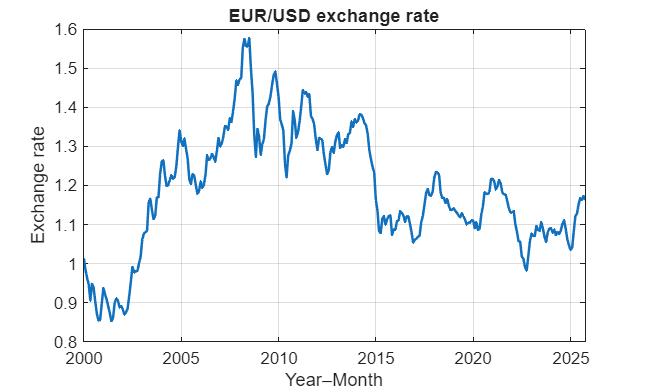

% Plot serie originale
plot(T.TIME_PERIOD, y, 'LineWidth', 1.5)
grid on
xlabel('Year–Month')
ylabel('Exchange rate')
title('EUR/USD exchange rate')

% ADF su serie originale

y = T.OBS_VALUE;           % estrai la serie
y = rmmissing(y);          % rimuovi eventuali NaN
[h,pValue,stat,cValue] = adftest(y);

if h
    disp("✅ La serie è stazionaria (si rifiuta l'ipotesi nulla di radice unitaria).")
else
    disp("⚠️ La serie NON è stazionaria (non si rifiuta l'ipotesi nulla).")
end

⚠️ La serie NON è stazionaria (non si rifiuta l'ipotesi nulla).



fprintf("p-value = %.4f\n", pValue)

p-value = 0.6884


% KPSS su serie originale

y = T.OBS_VALUE;
y = rmmissing(y);    % rimuovi NaN

[h,pValue,stat,cValue] = kpsstest(y);

if h
    disp("⚠️  Rifiuto H0: la serie NON è stazionaria (ha una radice unitaria).")
else
    disp("✅  Non rifiuto H0: la serie può essere considerata stazionaria.")
end

⚠️  Rifiuto H0: la serie NON è stazionaria (ha una radice unitaria).



fprintf("p-value = %.4f\n", pValue)

p-value = 0.0100


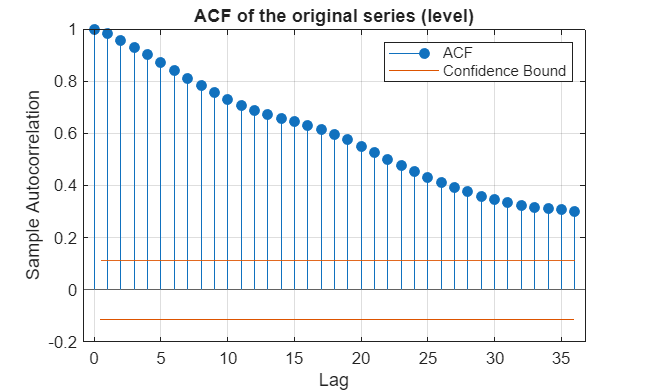

%% ACF e PACF sulla serie originale

% Plot ACF
figure;
autocorr(y, "NumLags", 36);
title('ACF of the original series (level)');
grid on;

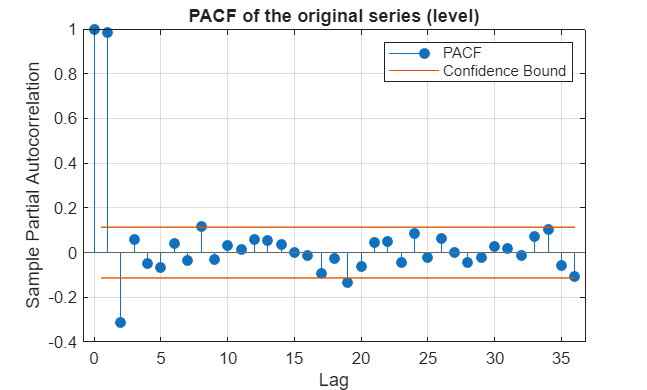


% Plot PACF
figure;
parcorr(y, "NumLags", 36);
title('PACF of the original series (level)');

grid on;

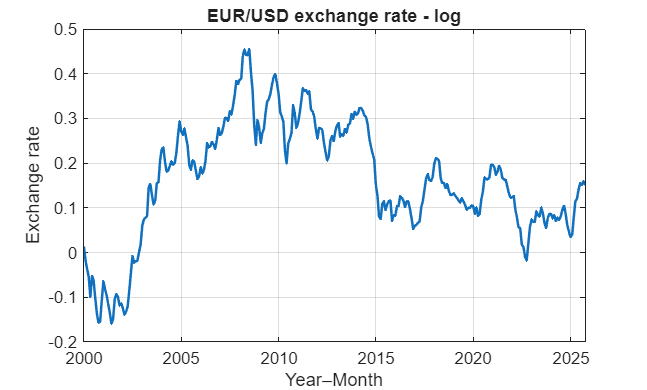

% Serie con LOG

%% 2. Log-livello e differenze

logy  = log(y);        % log-livello (spesso più comodo)

plot(dates, logy, 'LineWidth', 1.5)
grid on
xlabel('Year–Month')
ylabel('Exchange rate')
title('EUR/USD exchange rate - log')

%% 3. Test di stazionarietà su log-livello

disp('=== Test di stazionarietà sulla serie in log-livello ===')

=== Test di stazionarietà sulla serie in log-livello ===



% ADF: H0 = radice unitaria (non stazionaria)
[h_adf, p_adf] = adftest(logy);

if h_adf
    disp("✅ ADF: rifiuto H0 di radice unitaria → log(y) può essere considerata stazionaria.");
else
    disp("⚠️ ADF: NON rifiuto H0 → log(y) sembra avere una radice unitaria (non stazionaria).");
end

⚠️ ADF: NON rifiuto H0 → log(y) sembra avere una radice unitaria (non stazionaria).


fprintf("p-value ADF (logy) = %.4f\n\n", p_adf);

p-value ADF (logy) = 0.3694




% KPSS: H0 = stazionarietà
[h_kpss, p_kpss] = kpsstest(logy);

if h_kpss
    disp("⚠️ KPSS: rifiuto H0 di stazionarietà → log(y) NON è stazionaria.");
else
    disp("✅ KPSS: non rifiuto H0 → log(y) può essere considerata stazionaria.");
end

⚠️ KPSS: rifiuto H0 di stazionarietà → log(y) NON è stazionaria.


fprintf("p-value KPSS (logy) = %.4f\n\n", p_kpss);

p-value KPSS (logy) = 0.0100



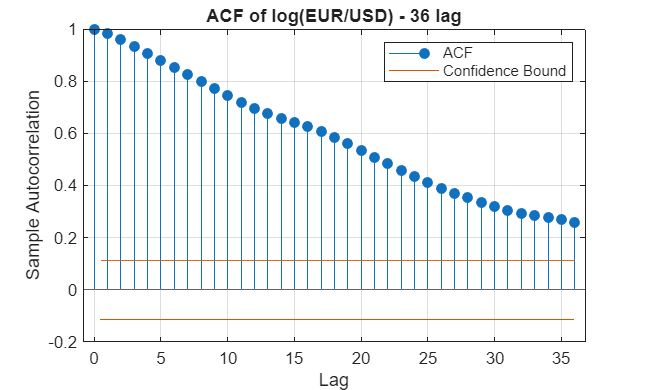

%% ACF e PACF del log-livello

figure;
autocorr(logy, 'NumLags', 36);
title('ACF of log(EUR/USD) - 36 lag');
grid on;

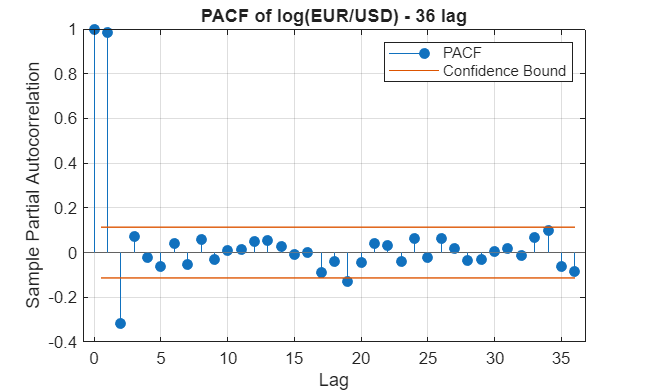


figure;
parcorr(logy, 'NumLags', 36);
title('PACF of log(EUR/USD) - 36 lag');
grid on;

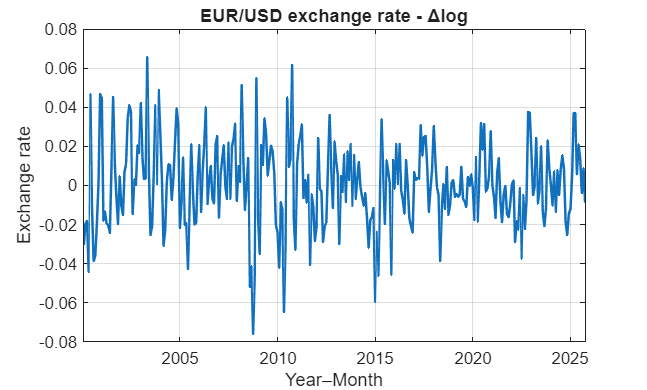

% Differenze log

dlogy = diff(logy);    % differenze dei log ≈ rendimento mensile

plot(dates(2:end), dlogy, 'LineWidth', 1.5)
grid on
xlabel('Year–Month')
ylabel('Exchange rate')
title('EUR/USD exchange rate - Δlog')


data = logy;                      % nostra serie (log-livello)
T    = length(data);
T0   = floor(0.8*T);              % 80% train, 20% test
h    = 1;

y_train = data(1:T0);
y_test  = data(T0+1:end);
%% 4. Test di stazionarietà sulla serie differenziata Δlogy

disp('=== Test di stazionarietà sulla serie differenziata Δlog(y) ===')

=== Test di stazionarietà sulla serie differenziata Δlog(y) ===



% ADF su Δlogy
[h_adf_d, p_adf_d] = adftest(dlogy);

if h_adf_d
    disp("✅ ADF: rifiuto H0 → Δlog(y) è stazionaria.");
else
    disp("⚠️ ADF: NON rifiuto H0 → Δlog(y) potrebbe non essere stazionaria.");
end

✅ ADF: rifiuto H0 → Δlog(y) è stazionaria.


fprintf("p-value ADF (Δlogy) = %.4f\n\n", p_adf_d);

p-value ADF (Δlogy) = 0.0010




% KPSS su Δlogy
[h_kpss_d, p_kpss_d] = kpsstest(dlogy);

if h_kpss_d
    disp("⚠️ KPSS: rifiuto H0 → Δlog(y) NON è stazionaria.");
else
    disp("✅ KPSS: non rifiuto H0 → Δlog(y) può essere considerata stazionaria.");
end

✅ KPSS: non rifiuto H0 → Δlog(y) può essere considerata stazionaria.


fprintf("p-value KPSS (Δlogy) = %.4f\n\n", p_kpss_d);

p-value KPSS (Δlogy) = 0.1000



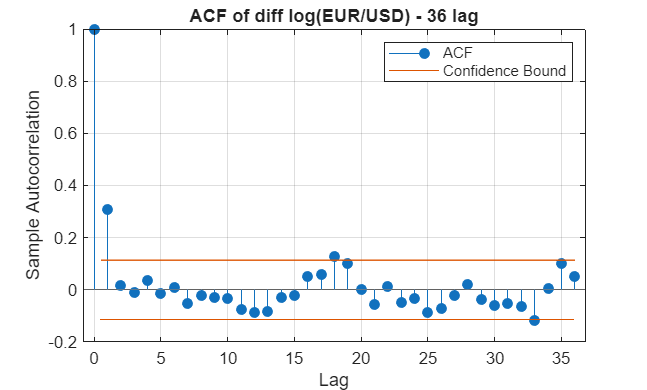


%% ACF e PACF del diff log-livello

figure;
autocorr(dlogy, 'NumLags', 36);
title('ACF of diff log(EUR/USD) - 36 lag');
grid on;

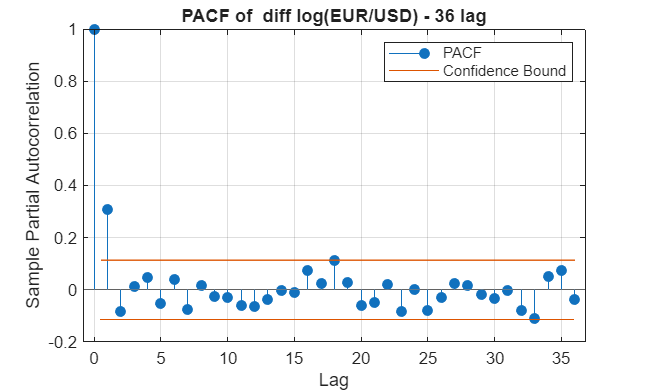


figure;
parcorr(dlogy, 'NumLags', 36);
title('PACF of  diff log(EUR/USD) - 36 lag');
grid on;

% RW with drift
data = logy;                      % nostra serie (log-livello)
model_rw = arima('D',1,'Constant',NaN,'Variance',NaN);
T    = length(data);
T0   = floor(0.8*T);              % 80% train, 20% test
h    = 1;

fore = NaN(T,1);                  % per salvare le previsioni

% Stima sul training set
est_rw = estimate(model_rw, y_train, 'Display', 'off');
disp('=== Benchmark stimato: ARIMA(0,1,0) con drift ===')

=== Benchmark stimato: ARIMA(0,1,0) con drift ===


est_rw

est_rw =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: 0.000614644
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000519014


% RW con drift (RWD)
m1 = arima('D',1,'Constant',NaN,'Variance',NaN);

jj = T0;
while jj < T
    % stima su [1 .. jj] (expanding window)
    m1 = estimate(m1, data(1:jj), 'Display','off');
    % forecast 1-step per jj+1
    fore(jj+1) = forecast(m1, h, data(1:jj));
    jj = jj + 1;
end

% errori di forecast nel test set
err_rw = data(T0+1:end) - fore(T0+1:end);

RMSFE_rw = sqrt(mean(err_rw.^2,'omitnan'));
MAFE_rw  = mean(abs(err_rw),'omitnan');

fprintf("RMSFE RW con drift = %.6f\n", RMSFE_rw);

RMSFE RW con drift = 0.016714


fprintf("MAFE  RW con drift = %.6f\n", MAFE_rw);

MAFE  RW con drift = 0.013290


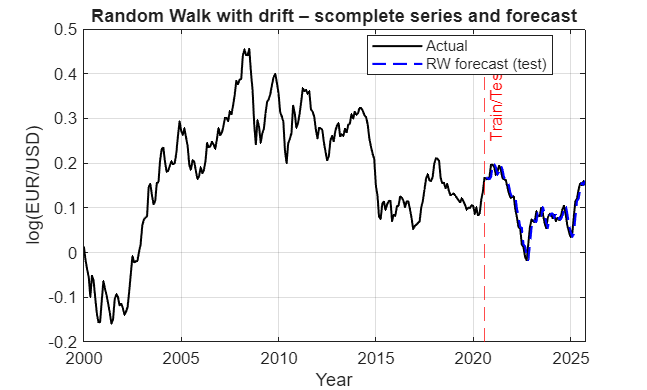



dates_test = dates(T0+1:end);

figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, fore(T0+1:end), '--b', 'LineWidth', 1.3);
xline(dates(T0),'--r','Train/Test split');
legend('Actual','RW forecast (test)','Location','best');
title('Random Walk with drift – scomplete series and forecast');
xlabel('Year');
ylabel('log(EUR/USD)');
grid on;

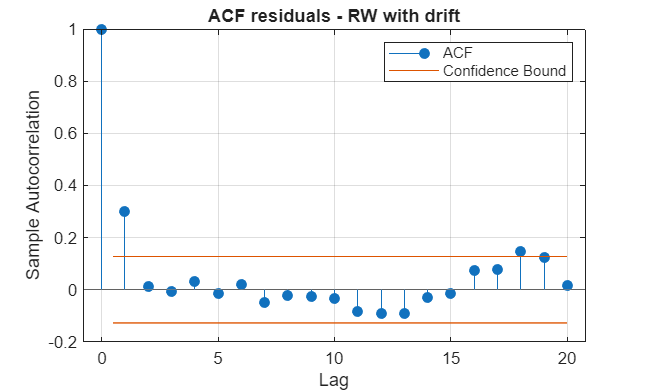


res_rw = infer(est_rw, y_train);

figure; autocorr(res_rw);
title('ACF residuals - RW with drift');

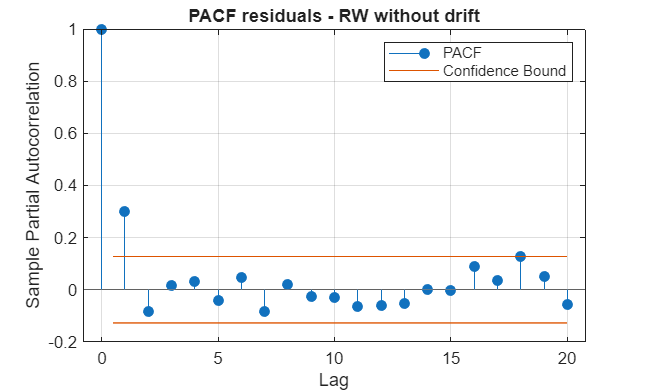


figure; parcorr(res_rw);
title('PACF residuals - RW without drift');


[h_lb_rw, p_lb_rw] = lbqtest(res_rw);
fprintf("Ljung-Box test on residuals RW: h=%d, p=%.4f\n", h_lb_rw, p_lb_rw);

Ljung-Box test on residuals RW: h=1, p=0.0017


%% RW SENZA DRIFT

data = logy;                      % nostra serie (log-livello)
T    = length(data);
T0   = floor(0.8*T);              % 80% train, 20% test
h    = 1;

fore0 = NaN(T,1);                 % previsioni RW senza drift

% --------------------------
% 1. Stima su training (solo per vedere i parametri e fare diagnostica)
% --------------------------
y_train = data(1:T0);
y_test  = data(T0+1:end);

m0 = arima('D',1,'Constant',0,'Variance',NaN);   % RW senza drift
est_rw0 = estimate(m0, y_train, 'Display','off');
disp('=== Benchmark stimato: ARIMA(0,1,0) SENZA drift ===')

=== Benchmark stimato: ARIMA(0,1,0) SENZA drift ===


est_rw0

est_rw0 =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: 0
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000519397


% --------------------------
% 2. Forecast 1-step in expanding window (test set)
% --------------------------
jj = T0;
while jj < T
    m0 = estimate(m0, data(1:jj), 'Display','off');          % stima su [1..jj]
    fore0(jj+1) = forecast(m0, h, data(1:jj));               % forecast per jj+1
    jj = jj + 1;
end

% --------------------------
% 3. Errori di forecast nel test set
% --------------------------
err_rw0 = data(T0+1:end) - fore0(T0+1:end);

RMSFE_rw0 = sqrt(mean(err_rw0.^2,'omitnan'));
MAFE_rw0  = mean(abs(err_rw0),'omitnan');

fprintf("RMSFE RW without drift = %.6f\n", RMSFE_rw0);

RMSFE RW without drift = 0.016693


fprintf("MAFE  RW without drift = %.6f\n", MAFE_rw0);

MAFE  RW without drift = 0.013179


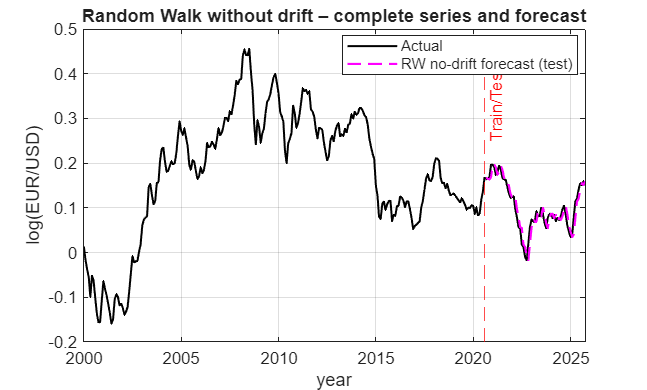


% --------------------------
% 4. Grafico serie completa + forecast test
% --------------------------
dates_test = dates(T0+1:end);

figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, fore0(T0+1:end), '--m', 'LineWidth', 1.3);
xline(dates(T0),'--r','Train/Test split');
legend('Actual','RW no-drift forecast (test)','Location','best');
title('Random Walk without drift – complete series and forecast');
xlabel('year');
ylabel('log(EUR/USD)');
grid on;

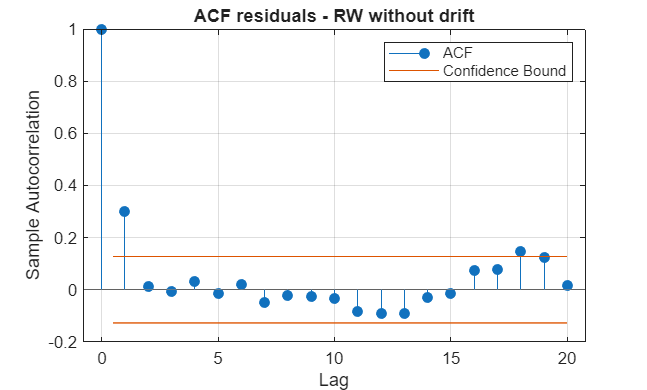


% --------------------------
% 5. Diagnostica residui sul training
% --------------------------
res_rw0 = infer(est_rw0, y_train);

figure; autocorr(res_rw0);
title('ACF residuals - RW without drift');


figure; parcorr(res_rw0);
title('PACF residuals - RW without drift');


[h_lb_rw0, p_lb_rw0] = lbqtest(res_rw0);
fprintf("Ljung-Box residuals RW without drift: h=%d, p=%.4f\n", h_lb_rw0, p_lb_rw0);

Ljung-Box residuals RW without drift: h=1, p=0.0017


%% AR(1): ARIMA(1,1,0) sul log-livello

h = 1;
fore_ar1 = NaN(T,1);

% --------------------------
% 1. Stima sul training (solo diagnostica e parametri)
% --------------------------
m_ar1 = arima('D',1,'ARLags',1,'Constant',NaN,'Variance',NaN);

est_ar1 = estimate(m_ar1, y_train, 'Display','off');
disp('=== Modello alternativo: ARIMA(1,1,0) (AR(1)) ===')

=== Modello alternativo: ARIMA(1,1,0) (AR(1)) ===


est_ar1

est_ar1 =   arima with properties:

     Description: "ARIMA(1,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 2
               D: 1
               Q: 0
        Constant: 0.000460268
              AR: {0.304224} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000471787


% --------------------------
% 2. Forecast 1-step (expanding window, stile prof)
% --------------------------
jj = T0;
while jj < T
    m_ar1 = estimate(m_ar1, data(1:jj), 'Display','off');    % stima su [1..jj]
    fore_ar1(jj+1) = forecast(m_ar1, h, data(1:jj));         % previsione per jj+1
    jj = jj + 1;
end

% --------------------------
% 3. Errori nel test set
% --------------------------
err_ar1 = data(T0+1:end) - fore_ar1(T0+1:end);

RMSFE_ar1 = sqrt(mean(err_ar1.^2,'omitnan'));
MAFE_ar1  = mean(abs(err_ar1),'omitnan');

fprintf("RMSFE AR(1) = %.6f\n", RMSFE_ar1);

RMSFE AR(1) = 0.015621


fprintf("MAFE  AR(1) = %.6f\n", MAFE_ar1);

MAFE  AR(1) = 0.012557


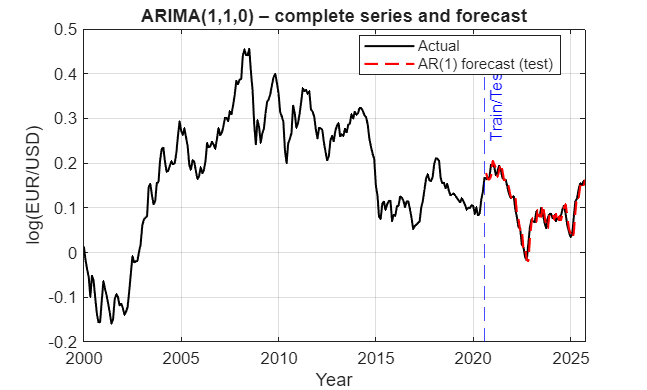


% --------------------------
% 4. Grafico completo: actual + forecast
% --------------------------
figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, fore_ar1(T0+1:end), '--r', 'LineWidth', 1.3);
xline(dates(T0),'--b','Train/Test split');
legend('Actual','AR(1) forecast (test)','Location','best');
title('ARIMA(1,1,0) – complete series and forecast');
xlabel('Year');
ylabel('log(EUR/USD)');
grid on;

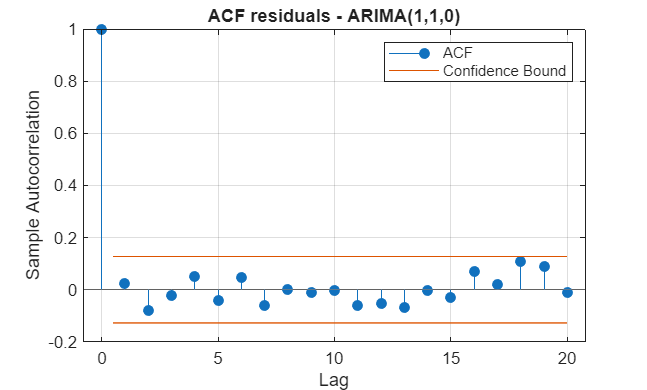


% --------------------------
% 5. Diagnostica residui TRAIN
% --------------------------
res_ar1 = infer(est_ar1, y_train);

figure; autocorr(res_ar1);
title('ACF residuals - ARIMA(1,1,0)');

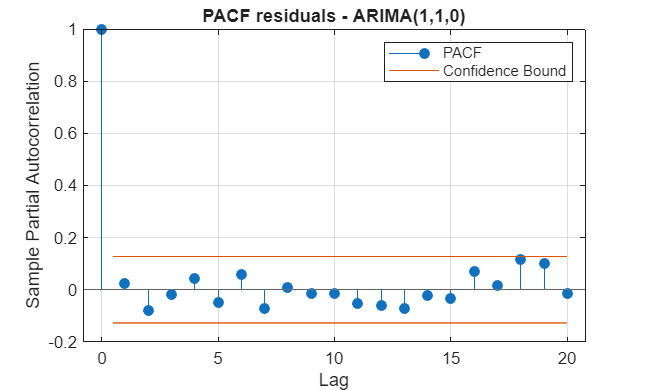


figure; parcorr(res_ar1);
title('PACF residuals - ARIMA(1,1,0)');


[h_lb_ar1, p_lb_ar1] = lbqtest(res_ar1);
fprintf("Ljung-Box residuals AR(1): h=%d, p=%.4f\n", h_lb_ar1, p_lb_ar1);

Ljung-Box residuals AR(1): h=0, p=0.8110


%% MA(1): ARIMA(0,1,1) sul log-livello

h = 1;
fore_ma1 = NaN(T,1);

% --------------------------
% 1. Stima sul training (diagnostica + parametri)
% --------------------------
m_ma1 = arima('D',1,'MALags',1,'Constant',NaN,'Variance',NaN);

est_ma1 = estimate(m_ma1, y_train, 'Display','off');
disp('=== Modello: ARIMA(0,1,1) (MA(1)) ===')

=== Modello: ARIMA(0,1,1) (MA(1)) ===


est_ma1

est_ma1 =   arima with properties:

     Description: "ARIMA(0,1,1) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 1
        Constant: 0.000715491
              AR: {}
             SAR: {}
              MA: {0.315297} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000469399


% --------------------------
% 2. Forecast 1-step (expanding window)
% --------------------------
jj = T0;
while jj < T
    m_ma1 = estimate(m_ma1, data(1:jj), 'Display','off');   % stima su [1..jj]
    fore_ma1(jj+1) = forecast(m_ma1, h, data(1:jj));        % previsione jj+1
    jj = jj + 1;
end

% --------------------------
% 3. Errori nel test set
% --------------------------
err_ma1 = data(T0+1:end) - fore_ma1(T0+1:end);

RMSFE_ma1 = sqrt(mean(err_ma1.^2,'omitnan'));
MAFE_ma1  = mean(abs(err_ma1),'omitnan');

fprintf("RMSFE MA(1) = %.6f\n", RMSFE_ma1);

RMSFE MA(1) = 0.015611


fprintf("MAFE  MA(1) = %.6f\n", MAFE_ma1);

MAFE  MA(1) = 0.012512


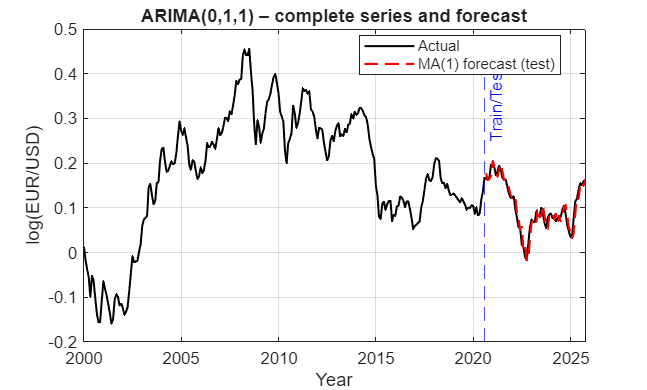


% --------------------------
% 4. Grafico completo: actual + forecast
% --------------------------
figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, fore_ma1(T0+1:end), '--r', 'LineWidth', 1.3);
xline(dates(T0),'--b','Train/Test split');
legend('Actual','MA(1) forecast (test)','Location','best');
title('ARIMA(0,1,1) – complete series and forecast');
xlabel('Year');
ylabel('log(EUR/USD)');
grid on;

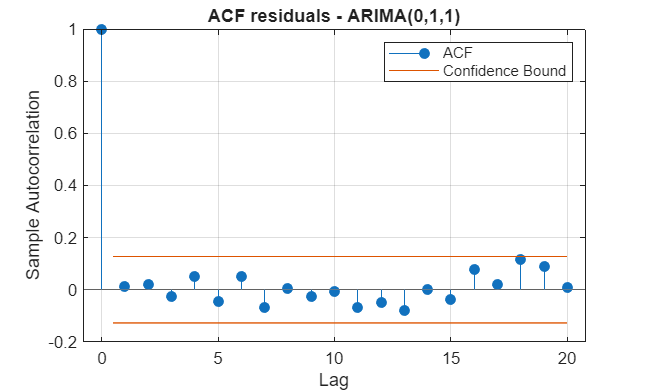


% --------------------------
% 5. Diagnostica residui TRAIN
% --------------------------
res_ma1 = infer(est_ma1, y_train);

figure; autocorr(res_ma1);
title('ACF residuals - ARIMA(0,1,1)');

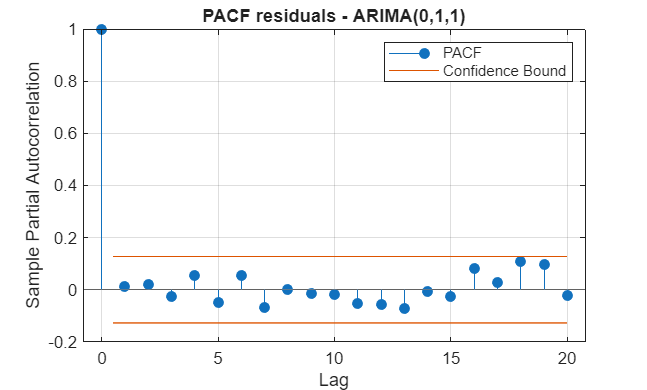


figure; parcorr(res_ma1);
title('PACF residuals - ARIMA(0,1,1)');


[h_lb_ma1, p_lb_ma1] = lbqtest(res_ma1);
fprintf("Ljung-Box residuals MA(1): h=%d, p=%.4f\n", h_lb_ma1, p_lb_ma1);

Ljung-Box residuals MA(1): h=0, p=0.7801


%% MA(2): ARIMA(0,1,2) sul log-livello (debug-ready, dimensioni corrette)

h = 1;  % forecast horizon
fore_ma2 = NaN(T,1);  % inizializzo forecast

% --------------------------
% 1. Stima sul training (diagnostica + parametri)
% --------------------------
m_ma2 = arima('D',1,'MALags',1:2,'Constant',NaN,'Variance',NaN);  % MA(2)
est_ma2 = estimate(m_ma2, y_train, 'Display','off');
disp('=== Modello: ARIMA(0,1,2) (MA(2)) ===')

=== Modello: ARIMA(0,1,2) (MA(2)) ===


est_ma2

est_ma2 =   arima with properties:

     Description: "ARIMA(0,1,2) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 2
        Constant: 0.000729545
              AR: {}
             SAR: {}
              MA: {0.328771 0.0319447} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000468874


% --------------------------
% 2. Forecast 1-step (expanding window) con controllo dimensioni
% --------------------------
for jj = T0:T-1  % loop fino a T-1 incluso
    % Stima del modello sull'espanding window
    m_ma2 = estimate(m_ma2, data(1:jj), 'Display','off');

    % Forecast 1-step
    f = forecast(m_ma2, h, data(1:jj));

    % Controllo dimensioni forecast
    if numel(f) ~= h
        warning('Forecast dimension mismatch at jj=%d: expected %d, got %d', jj, h, numel(f));
    end

    % Assicuro compatibilità con fore_ma2
    fore_ma2(jj+1) = f(1);  % prendo solo il primo elemento
end

% --------------------------
% 3. Errori nel test set con controllo dimensioni
% --------------------------
y_test = data(T0+1:end);
forecast_test = fore_ma2(T0+1:end);

if numel(y_test) ~= numel(forecast_test)
    error('Dimension mismatch: y_test (%d) vs forecast_test (%d)', ...
        numel(y_test), numel(forecast_test));
end

err_ma2 = y_test - forecast_test;

RMSFE_ma2 = sqrt(mean(err_ma2.^2,'omitnan'));
MAFE_ma2  = mean(abs(err_ma2),'omitnan');

fprintf("RMSFE MA(2) = %.6f\n", RMSFE_ma2);

RMSFE MA(2) = 0.015566


fprintf("MAFE  MA(2) = %.6f\n", MAFE_ma2);

MAFE  MA(2) = 0.012489


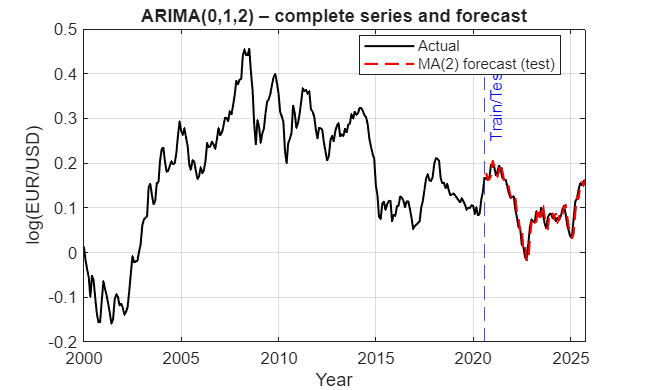


% --------------------------
% 4. Grafico completo: actual + forecast
% --------------------------
figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, forecast_test, '--r', 'LineWidth', 1.3);
xline(dates(T0),'--b','Train/Test split');
legend('Actual','MA(2) forecast (test)','Location','best');
title('ARIMA(0,1,2) – complete series and forecast');
xlabel('Year');
ylabel('log(EUR/USD)');
grid on;

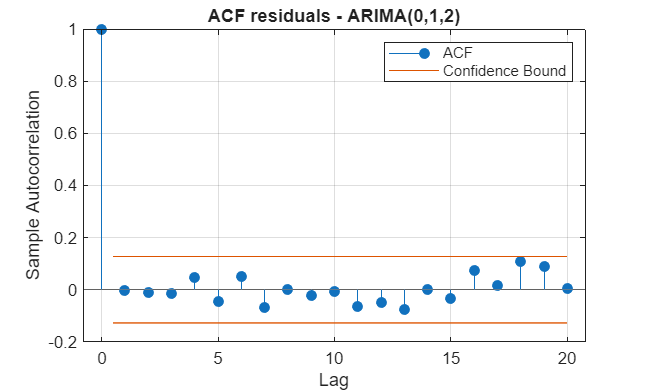


% --------------------------
% 5. Diagnostica residui TRAIN
% --------------------------
res_ma2 = infer(est_ma2, y_train);

figure; autocorr(res_ma2);
title('ACF residuals - ARIMA(0,1,2)');

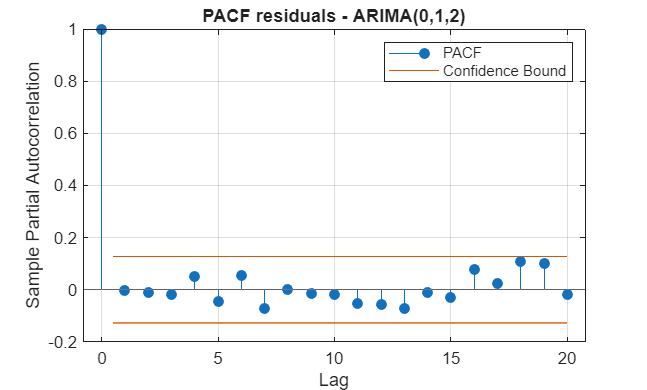


figure; parcorr(res_ma2);
title('PACF residuals - ARIMA(0,1,2)');


[h_lb_ma2, p_lb_ma2] = lbqtest(res_ma2);
fprintf("Ljung-Box residuals MA(2): h=%d, p=%.4f\n", h_lb_ma2, p_lb_ma2);

Ljung-Box residuals MA(2): h=0, p=0.8444


%% AR(2): ARIMA(2,1,0) sul log-livello

h = 1;
fore_ar2 = NaN(T,1);

% --------------------------
% 1. Stima sul training (solo diagnostica e parametri)
% --------------------------
m_ar2 = arima('D',1,'ARLags',1:2,'Constant',NaN,'Variance',NaN);

est_ar2 = estimate(m_ar2, y_train, 'Display','off');
disp('=== Modello alternativo: ARIMA(2,1,0) ===')

=== Modello alternativo: ARIMA(2,1,0) ===


est_ar2

est_ar2 =   arima with properties:

     Description: "ARIMA(2,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 3
               D: 1
               Q: 0
        Constant: 0.000464842
              AR: {0.328376 -0.0830446} at lags [1 2]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000468613


% --------------------------
% 2. Forecast 1-step (expanding window), esattamente stile PROF
% --------------------------
jj = T0;
while jj < T
    m_ar2 = estimate(m_ar2, data(1:jj), 'Display','off');   % stima su [1..jj]
    fore_ar2(jj+1) = forecast(m_ar2, h, data(1:jj));        % previsione per jj+1
    jj = jj + 1;
end

% --------------------------
% 3. Errori nel test set
% --------------------------
err_ar2 = data(T0+1:end) - fore_ar2(T0+1:end);

RMSFE_ar2 = sqrt(mean(err_ar2.^2,'omitnan'));
MAFE_ar2  = mean(abs(err_ar2),'omitnan');

fprintf("RMSFE AR(2) = %.6f\n", RMSFE_ar2);

RMSFE AR(2) = 0.015548


fprintf("MAFE  AR(2) = %.6f\n", MAFE_ar2);

MAFE  AR(2) = 0.012474


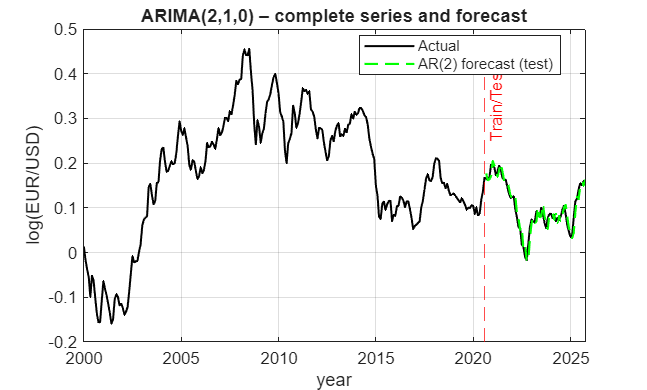


% --------------------------
% 4. Grafico completo: actual + forecast
% --------------------------
figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, fore_ar2(T0+1:end), '--g', 'LineWidth', 1.3);
xline(dates(T0),'--r','Train/Test split');
legend('Actual','AR(2) forecast (test)','Location','best');
title('ARIMA(2,1,0) – complete series and forecast');
xlabel('year');
ylabel('log(EUR/USD)');
grid on;

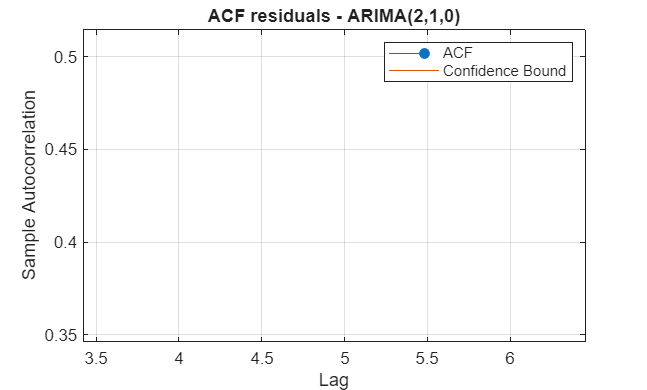


% --------------------------
% 5. Diagnostica residui TRAIN
% --------------------------
res_ar2 = infer(est_ar2, y_train);

figure; autocorr(res_ar2);
title('ACF residuals - ARIMA(2,1,0)');

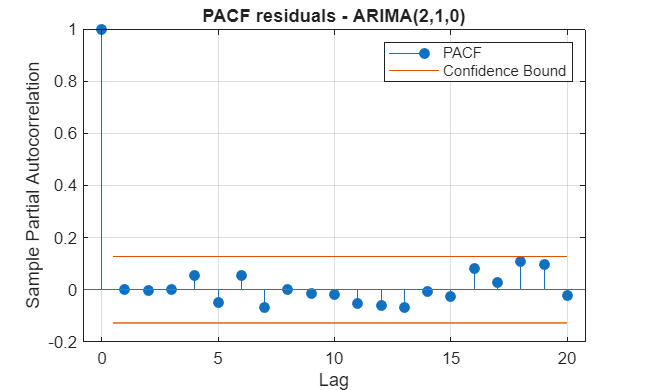


figure; parcorr(res_ar2);
title('PACF residuals - ARIMA(2,1,0)');


[h_lb_ar2, p_lb_ar2] = lbqtest(res_ar2);
fprintf("Ljung-Box residuals AR(2): h=%d, p=%.4f\n", h_lb_ar2, p_lb_ar2);

Ljung-Box residuals AR(2): h=0, p=0.8320


%% AR(3): ARIMA(3,1,0) sul log-livello

h = 1;
fore_ar3 = NaN(T,1);

% --------------------------
% 1. Stima sul training (solo diagnostica e parametri)
% --------------------------
m_ar3 = arima('D',1,'ARLags',1:3,'Constant',NaN,'Variance',NaN);

est_ar3 = estimate(m_ar3, y_train, 'Display','off');
disp('=== Modello alternativo: ARIMA(3,1,0) ===')

=== Modello alternativo: ARIMA(3,1,0) ===


est_ar3

est_ar3 =   arima with properties:

     Description: "ARIMA(3,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 4
               D: 1
               Q: 0
        Constant: 0.000465057
              AR: {0.330003 -0.0885657 0.0178072} at lags [1 2 3]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000468469


% --------------------------
% 2. Forecast 1-step (expanding window, stile prof)
% --------------------------
jj = T0;
while jj < T
    m_ar3 = estimate(m_ar3, data(1:jj), 'Display','off');   % stima su [1..jj]
    fore_ar3(jj+1) = forecast(m_ar3, h, data(1:jj));        % previsione per jj+1
    jj = jj + 1;
end

% --------------------------
% 3. Errori nel test set
% --------------------------
err_ar3 = data(T0+1:end) - fore_ar3(T0+1:end);

RMSFE_ar3 = sqrt(mean(err_ar3.^2,'omitnan'));
MAFE_ar3  = mean(abs(err_ar3),'omitnan');

fprintf("RMSFE AR(3) = %.6f\n", RMSFE_ar3);

RMSFE AR(3) = 0.015558


fprintf("MAFE  AR(3) = %.6f\n", MAFE_ar3);

MAFE  AR(3) = 0.012480


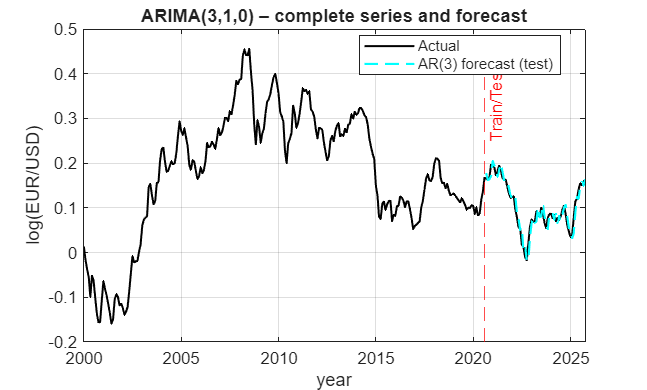


% --------------------------
% 4. Grafico completo: actual + forecast
% --------------------------
figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, fore_ar3(T0+1:end), '--c', 'LineWidth', 1.3);
xline(dates(T0),'--r','Train/Test split');
legend('Actual','AR(3) forecast (test)','Location','best');
title('ARIMA(3,1,0) – complete series and forecast');
xlabel('year');
ylabel('log(EUR/USD)');
grid on;

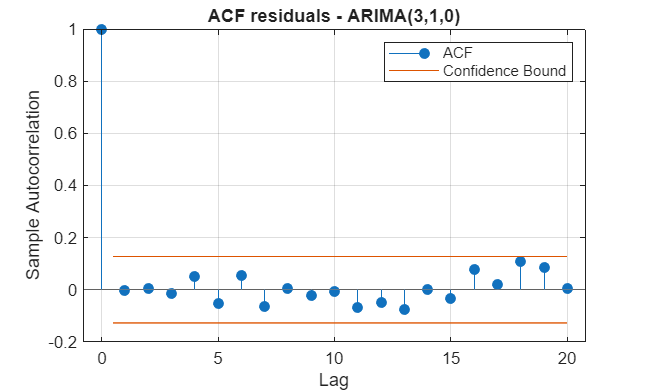


% --------------------------
% 5. Diagnostica residui TRAIN
% --------------------------
res_ar3 = infer(est_ar3, y_train);

figure; autocorr(res_ar3);
title('ACF residuals - ARIMA(3,1,0)');

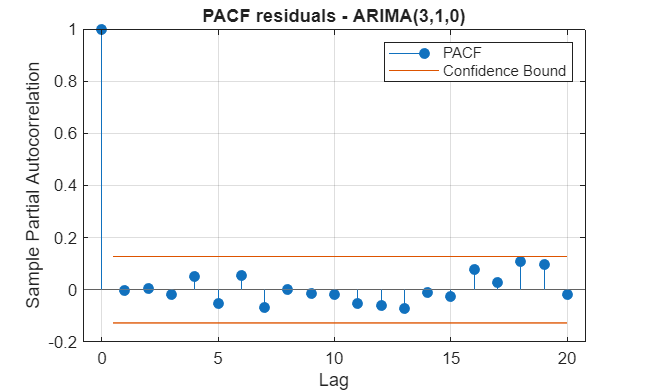


figure; parcorr(res_ar3);
title('PACF residuals - ARIMA(3,1,0)');


[h_lb_ar3, p_lb_ar3] = lbqtest(res_ar3);
fprintf("Ljung-Box residuals AR(3): h=%d, p=%.4f\n", h_lb_ar3, p_lb_ar3);

Ljung-Box residuals AR(3): h=0, p=0.8254


%% Confronto AR(p) per p = 1,...,12 sul TRAINING

Pmax = 12;

aic_ar = NaN(Pmax,1);
bic_ar = NaN(Pmax,1);

for p = 1:Pmax

    % ARIMA(p,1,0) sul log-livello (con drift)
    Mdl = arima(p, 1, 0);   % sintassi tipo prof

    % stima SOLO sul training
    mhat = estimate(Mdl, y_train, 'Display','off');

    % usa summarize per estrarre AIC e BIC (come nel codice del prof)
    summhat = summarize(mhat);
    aic_ar(p) = summhat.AIC;
    bic_ar(p) = summhat.BIC;
end

% Tabella risultati
p_values = (1:Pmax)';
Results_AR = table(p_values, aic_ar, bic_ar, ...
    'VariableNames', {'p','AIC','BIC'});

disp('=== AIC/BIC for ARIMA(p,1,0) ===');

=== AIC/BIC for ARIMA(p,1,0) ===


disp(Results_AR);

    p       AIC        BIC  
    __    _______    _______

     1    -1189.6    -1179.1
     2    -1189.3    -1175.3
     3    -1187.4    -1169.8
     4    -1185.7    -1164.6
     5    -1184.3    -1159.7
     6    -1182.9    -1154.8
     7    -1182.8    -1151.2
     8    -1180.9    -1145.8
     9    -1179.1    -1140.5
    10    -1177.4    -1135.2
    11    -1176.6    -1130.9
    12    -1175.8    -1126.6



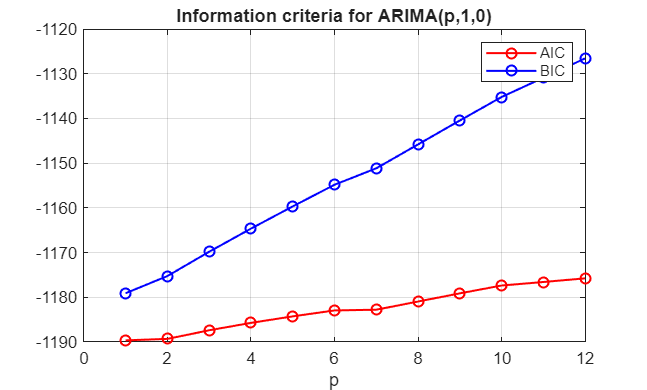


figure;
plot(1:Pmax, aic_ar','-or', 1:Pmax, bic_ar','-ob', 'LineWidth',1.2);
grid on;
legend('AIC','BIC');
xlabel('p');
title('Information criteria for ARIMA(p,1,0)');

## ARIMA(1,1,1) sul log-livello (ARMA(1,1) sulle differenze)

h = 1;
fore_111 = NaN(T,1);

% --------------------------
% 1. Stima sul TRAINING (parametri + AIC/BIC)
% --------------------------
m_111 = arima('D',1, ...
              'ARLags',1, ...
              'MALags',1, ...
              'Constant',NaN, ...
              'Variance',NaN);

est_111 = estimate(m_111, y_train, 'Display','off');
disp('=== Modello alternativo: ARIMA(1,1,1) ===')

=== Modello alternativo: ARIMA(1,1,1) ===


est_111

est_111 =   arima with properties:

     Description: "ARIMA(1,1,1) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 2
               D: 1
               Q: 1
        Constant: 0.000618616
              AR: {0.0959778} at lag [1]
             SAR: {}
              MA: {0.232307} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000468825


% AIC/BIC del modello (per confronto con ARIMA(1,1,0))
summ_111 = summarize(est_111);
AIC_111 = summ_111.AIC;
BIC_111 = summ_111.BIC;
fprintf('AIC ARIMA(1,1,1) = %.2f\n', AIC_111);

AIC ARIMA(1,1,1) = -1189.19


fprintf('BIC ARIMA(1,1,1) = %.2f\n', BIC_111);

BIC ARIMA(1,1,1) = -1175.14



% --------------------------
% 2. Forecast 1-step (expanding window, stile prof)
% --------------------------
jj = T0;
while jj < T
    m_111 = estimate(m_111, data(1:jj), 'Display','off');      % stima su [1..jj]
    fore_111(jj+1) = forecast(m_111, h, data(1:jj));           % forecast per jj+1
    jj = jj + 1;
end

% --------------------------
% 3. Errori nel TEST set
% --------------------------
err_111 = data(T0+1:end) - fore_111(T0+1:end);

RMSFE_111 = sqrt(mean(err_111.^2,'omitnan'));
MAFE_111  = mean(abs(err_111),'omitnan');

fprintf("RMSFE ARIMA(1,1,1) = %.6f\n", RMSFE_111);

RMSFE ARIMA(1,1,1) = 0.015570


fprintf("MAFE  ARIMA(1,1,1) = %.6f\n", MAFE_111);

MAFE  ARIMA(1,1,1) = 0.012495


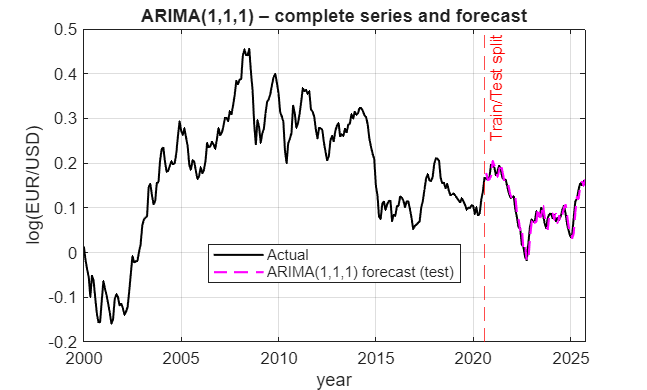


% --------------------------
% 4. Grafico completo: actual + forecast
% --------------------------
figure;
plot(dates, data, 'k', 'LineWidth', 1.2); hold on;
plot(dates_test, fore_111(T0+1:end), '--m', 'LineWidth', 1.3);
xline(dates(T0),'--r','Train/Test split');
legend('Actual','ARIMA(1,1,1) forecast (test)','Location','best');
title('ARIMA(1,1,1) – complete series and forecast');
xlabel('year');
ylabel('log(EUR/USD)');
grid on;

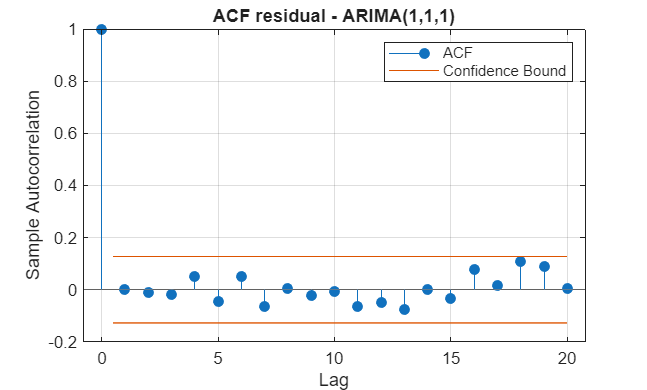


% --------------------------
% 5. Diagnostica residui sul TRAIN
% --------------------------
res_111 = infer(est_111, y_train);

figure; autocorr(res_111);
title('ACF residual - ARIMA(1,1,1)');

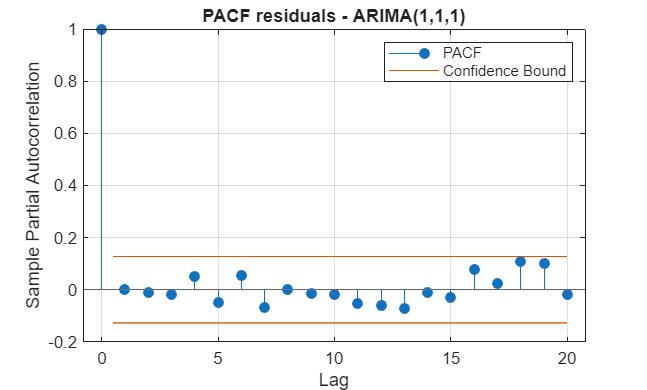


figure; parcorr(res_111);
title('PACF residuals - ARIMA(1,1,1)');


[h_lb_111, p_lb_111] = lbqtest(res_111);
fprintf("Ljung-Box residuals ARIMA(1,1,1): h=%d, p=%.4f\n", h_lb_111, p_lb_111);

Ljung-Box residuals ARIMA(1,1,1): h=0, p=0.8380


% Economic Policy Uncertainty (mensile, versione USA e Europe) %Ok USA-EUR
% PMI (USA ed EA, oppure differenziale)                        %No
% VIX (Volatilità finanziaria - paura) (media mensile)         %Ok USA
% Commodity prices (petrolio, oro)                             %OK

% Stock Indices (S&P 500, Euro Stoxx50)                        %OK EUR(1980),
% 2015 USD


% Consumer confidence
% Economic surprise index
% Economic sentiment and confidence indicators by sector - monthly data 

%% 1. Leggo FRED-MD con formato data corretto

% Opzioni di import: forzo il formato della colonna 'sasdate'
opts = detectImportOptions("2025-10-md.csv", 'VariableNamingRule','preserve');

% dico a MATLAB che 'sasdate' è datetime in formato USA MM/dd/yyyy
opts = setvartype(opts, "sasdate", "datetime");
opts = setvaropts(opts, "sasdate", "InputFormat", "MM/dd/yyyy");

US = readtable("2025-10-md.csv", opts);

%% 2. Prima riga = codici di trasformazione

% La prima riga contiene i codici (1,2,5,...) per ogni variabile (esclusa sasdate)
transf_codes = US{1, 2:end};   % da colonna 2 in poi (colonna 1 = sasdate)

% Tolgo la riga "Transform:" dal dataset
US(1,:) = [];

%% 3. Date mensili e rimozione della colonna sasdate

USdate = US.sasdate;   % già datetime grazie a opts
US.sasdate = [];       % tolgo la colonna dal pannello di variabili

%% 4. Seleziono le variabili che abbiamo deciso

us_vars = { ...
    'RPI','W875RX1','DPCERA3M086SBEA','CMRMTSPLx','RETAILx', ...
    'INDPRO','IPFPNSS','IPFINAL','IPCONGD','HOUST','PAYEMS', ...
    'UNRATE', ...
    'CPIAUCSL','CUSR0000SA0L2','CUSR0000SA0L5','PCEPI', ...
    'FEDFUNDS','GS1','GS10', ...
    'UMCSENTx','VIXCLSx'};

% Pannello USA (T x N)
XUS_raw = US{:, us_vars};

%% ============================
%  0) PULIZIA
% ============================

%% ============================
%  1) IMPORTA EAdata.xlsx
% ============================
opts = detectImportOptions("EAdata.xlsx", "VariableNamingRule","preserve");

% Formato rilevato: 01/01/00 00:00
opts = setvartype(opts, "Time", "datetime");
opts = setvaropts(opts, "Time", "InputFormat", "dd/MM/yy HH:mm");

EA = readtable("EAdata.xlsx", opts);

% Visualizzazione anno-mese
EA.Time.Format = "yyyy-MM";

dates_EA = EA.Time;

%% ============================
%  2) LE VARIABILI CHE VOGLIO USARE
% ============================
eu_vars = { ...
    'IPMN_EA','IPING_EA','IPCAG_EA','IPCOG_EA','IPNRG_EA', ...
    'HICPOV_EA','HICPNEF_EA','HICPG_EA','HICPNG_EA', ...
    'PPICAG_EA','PPICOG_EA','PPING_EA', ...
    'IRT3M_EA','IRT6M_EA','LTRT_EA', ...
    'ICONFIX_EA','ESENTIX_EA','CCONFIX_EA','BCI_EA','CCI_EA' ...
    };

%% ============================
%  3) VERIFICO QUALI ESISTONO
% ============================
allVars    = EA.Properties.VariableNames;
vars_exist = eu_vars( ismember(eu_vars, allVars) );
vars_missing = setdiff(eu_vars, vars_exist);

if ~isempty(vars_missing)
    fprintf("\n⚠ Variabili NON trovate:\n");
    disp(vars_missing);
end


⚠ Variabili NON trovate:


    {'IRT3M_EA'}    {'IRT6M_EA'}    {'LTRT_EA'}    {'PPING_EA'}



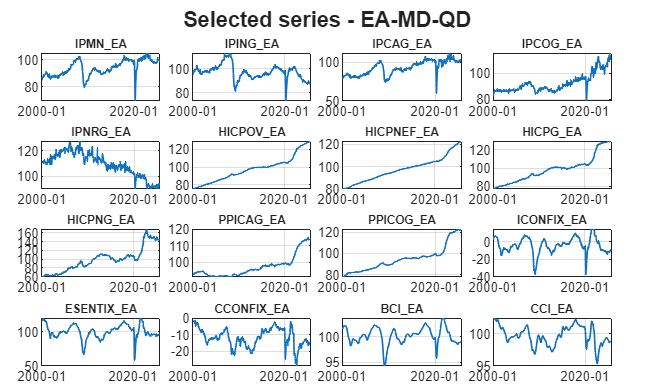


vars_exist = vars_exist(:)';  % la rendo cell-row

%% ============================
%  4) COSTRUISCO MATRICE X
% ============================
X_EA_raw = EA{:, vars_exist};
nSeries  = numel(vars_exist);

%% ============================
%  5) MULTIPANNELLO (FUNZIONA SU TUTTO)
% ============================
nRows = ceil(sqrt(nSeries));
nCols = ceil(nSeries / nRows);

figure;
tiledlayout(nRows, nCols, 'TileSpacing','compact','Padding','compact');

for j = 1:nSeries
    nexttile;
    plot(dates_EA, X_EA_raw(:,j), 'LineWidth', 1);
    title(vars_exist{j}, 'Interpreter','none', 'FontSize',7);
    grid on;

    % 🟢 questo funziona SEMPRE, anche su MATLAB vecchio
    datetick('x', 'yyyy-mm', 'keeplimits')
end

sgtitle('Selected series - EA-MD-QD', 'FontWeight','bold');

%% ================================================================
% 1) ALLINEAMENTO DELLE DATE USA – EURO AREA
% ================================================================

% Trova le date comuni (intersection)
[common_dates, idx_US, idx_EA] = intersect(USdate, dates_EA);

% Allineo le matrici alle stesse date
X_US_aligned = XUS_raw(idx_US, :);
X_EA_aligned = X_EA_raw(idx_EA, :);

fprintf("\nDate comuni trovate: %d osservazioni\n", numel(common_dates));


Date comuni trovate: 309 osservazioni




%% ================================================================
% 2) COSTRUZIONE DEL PANNELLO COMPLETO (USA + EA)
% ================================================================

% Concateno orizzontalmente → tutte le variabili macro
X_all = [X_US_aligned, X_EA_aligned];

[T, N] = size(X_all);
fprintf("Pannello macro USA + EA: %d osservazioni, %d variabili\n", T, N);

Pannello macro USA + EA: 309 osservazioni, 37 variabili




%% ================================================================
% 3) STANDARDIZZAZIONE (z-score)
%  (ogni variabile con media 0, varianza 1)
% ================================================================

X_std = (X_all - mean(X_all,1)) ./ std(X_all,[],1);

%PROVA CON DELTA LOG PER PRIMO MODELLO     OK PRESTAZIONI MIGLIORI
% 
% PCA AND THEN AR-X with 2 autoregressive components, USING FIRST FACTOR
%AS EXPLANATORY VARIABLE
%% =====================================================================
% 0) PULIZIA
% =====================================================================

date_cut = datetime(2000,1,1);   % lavoriamo dal 2000 in poi

%% =====================================================================
% 1) IMPORTA FRED-MD (USA)
% =====================================================================

optsUS = detectImportOptions("2025-10-md.csv", "VariableNamingRule","preserve");
optsUS = setvartype(optsUS, "sasdate", "datetime");
optsUS = setvaropts(optsUS, "sasdate", "InputFormat","MM/dd/yyyy");

US = readtable("2025-10-md.csv", optsUS);

% Prima riga = codici di trasformazione, elimina
US(1,:) = [];

USdate = US.sasdate;
US.sasdate = [];

us_vars = { ...
    'RPI','W875RX1','DPCERA3M086SBEA','CMRMTSPLx','RETAILx', ...
    'INDPRO','IPFPNSS','IPFINAL','IPCONGD','HOUST','PAYEMS', ...
    'UNRATE', ...
    'CPIAUCSL','CUSR0000SA0L2','CUSR0000SA0L5','PCEPI', ...
    'FEDFUNDS','GS1','GS10', ...
    'UMCSENTx','VIXCLSx'};

XUS_raw = US{:, us_vars};

% Taglio dal 2000
idxUS = USdate >= date_cut;
USdate_cut = USdate(idxUS);
XUS_cut    = XUS_raw(idxUS,:);

%% =====================================================================
% 2) IMPORTA EAdata (Euro Area)
% =====================================================================

optsEA = detectImportOptions("EAdata.xlsx", "VariableNamingRule","preserve");
optsEA = setvartype(optsEA, "Time", "datetime");
optsEA = setvaropts(optsEA, "Time", "InputFormat","dd/MM/yy HH:mm");

EA = readtable("EAdata.xlsx", optsEA);

dates_EA = EA.Time;
dates_EA.Format = "yyyy-MM";

eu_vars = { ...
    'IPMN_EA','IPING_EA','IPCAG_EA','IPCOG_EA','IPNRG_EA', ...
    'HICPNEF_EA','HICPG_EA','HICPNG_EA', ...
    'PPICAG_EA','PPICOG_EA','PPING_EA', ...
    'IRT3M_EA','LTRT_EA', ...
    'ICONFIX_EA','ESENTIX_EA','CCONFIX_EA','BCI_EA','CCI_EA'};

eu_vars = eu_vars(ismember(eu_vars, EA.Properties.VariableNames));
XEA_raw = EA{:, eu_vars};

idxEA = dates_EA >= date_cut;
EAdate_cut = dates_EA(idxEA);
XEA_cut    = XEA_raw(idxEA,:);

fprintf("USA osservazioni >=2000: %d\n", sum(idxUS));

USA osservazioni >=2000: 309


fprintf("EA  osservazioni >=2000: %d\n", sum(idxEA));

EA  osservazioni >=2000: 310



%% =====================================================================
% 3) ALLINEAMENTO USA / EA AL MESE
% =====================================================================

US_month = dateshift(USdate_cut,'start','month');
EA_month = dateshift(EAdate_cut,'start','month');

US_month.Format = "yyyy-MM";
EA_month.Format = "yyyy-MM";

[common_dates_macro, idx_US, idx_EA] = intersect(US_month, EA_month);

X_US = XUS_cut(idx_US,:);
X_EA = XEA_cut(idx_EA,:);

%% =====================================================================
% 4) PANNELLO COMPLETO + RIMOZIONE NaN
% =====================================================================

X_all = [X_US, X_EA];
rows_ok = all(~isnan(X_all),2);

X_all_clean  = X_all(rows_ok,:);
dates_macro  = common_dates_macro(rows_ok);

[Tmacro, Nmacro] = size(X_all_clean);
fprintf("Pannello macro pulito: %d osservazioni × %d variabili\n", Tmacro, Nmacro);

Pannello macro pulito: 307 osservazioni × 36 variabili


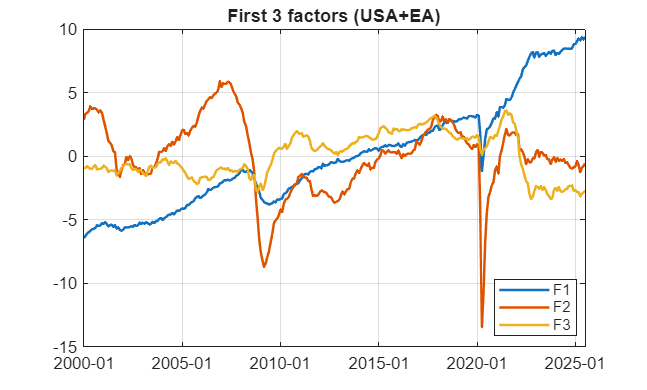


%% =====================================================================
% 5) STANDARDIZZAZIONE E PCA
% =====================================================================

X_std = (X_all_clean - mean(X_all_clean,1)) ./ std(X_all_clean,[],1);

[U,S,V] = svd(X_std,'econ');
F_all   = U*S;          % fattori "statici" (alla Stock–Watson)
F_all   = F_all(:,1:3); % primi 3 fattori

F1 = F_all(:,1);
F2 = F_all(:,2);
F3 = F_all(:,3);

figure;
plot(dates_macro, F1,'LineWidth',1.5); hold on
plot(dates_macro, F2,'LineWidth',1.5);
plot(dates_macro, F3,'LineWidth',1.5);
legend('F1','F2','F3','Location','best');
title('First 3 factors (USA+EA)');
grid on; datetick('x','yyyy-mm','keeplimits');

%% =====================================================================
% 6) IMPORT EUR/USD AND ALIGN WITH MACRO DATES
% =====================================================================

FX = readtable("ert_bil_eur_m__custom_18765067_linear_2_0.csv");


FX.TIME_PERIOD = datetime(string(FX.TIME_PERIOD),'InputFormat','yyyy-MM');
FX.TIME_PERIOD.Format = "yyyy-MM";

dates_fx = FX.TIME_PERIOD;
y_level  = FX.OBS_VALUE;
y_log    = log(y_level); % log-level of EUR/USD

idxFX = dates_fx >= date_cut;
dates_fx_cut = dates_fx(idxFX);
y_log_cut    = y_log(idxFX);

[dates_model, idxF, idxFX2] = intersect(dates_macro, dates_fx_cut);

F_model   = F_all(idxF,:);       % aligned factors
y_log_mod = y_log_cut(idxFX2);   % log(EUR/USD)
fprintf("Aligned macro + FX observations: %d\n", numel(dates_model));

Aligned macro + FX observations: 307



%% =====================================================================
% 7) COSTRUISCO VARIABILI PER IL DFM SU Δ log-livello, fattore laggato
%% =====================================================================

% differenze logaritmiche del tasso di cambio
y_full = diff(y_log_mod);  % Δ log(EUR/USD)

% differenze prime del fattore (per stazionarizzare)
F1_full = diff(F_model(:,1)); % ΔF1_t

% Creiamo il lag 1 per ΔF1 (ΔF1_{t-1})
F1_lag = [NaN; F1_full(1:end-1)];

% Lag di Δy (AR(2))
y_lag_1 = [NaN; y_full(1:end-1)];
y_lag_2 = [NaN; NaN; y_full(1:end-2)];

% Eliminiamo prime due osservazioni (mancano Δy_{t-1}, Δy_{t-2} e ΔF1_{t-1})
y_dep   = y_full(3:end);
y_lag_1 = y_lag_1(3:end);
y_lag_2 = y_lag_2(3:end);
F1_reg  = F1_lag(3:end);   % allineamento ΔF1 laggato con Δy
dates_y = dates_model(3:end);

Ttot_DFM    = length(y_dep);
T_train_DFM = floor(0.8 * Ttot_DFM);
idx_test_DFM = (T_train_DFM+1):Ttot_DFM;

fprintf("DFM (1 fattore laggato, AR(2)-X, Δlog): osservazioni totali = %d | train = %d | test = %d\n", ...
    Ttot_DFM, T_train_DFM, Ttot_DFM - T_train_DFM);

DFM (1 fattore laggato, AR(2)-X, Δlog): osservazioni totali = 304 | train = 243 | test = 61



%% =====================================================================
% 8) DFM (AR(2) + ΔF1 laggato) — EXPANDING WINDOW
%% =====================================================================

y_hat_DFM = NaN(Ttot_DFM,1);

for t = T_train_DFM+1:Ttot_DFM

    y_est = y_dep(1:t-1);
    X_est = [ones(t-1,1), y_lag_1(1:t-1), y_lag_2(1:t-1), F1_reg(1:t-1)];
    % regressori: [1 Δy_{t-1} Δy_{t-2} ΔF1_{t-1}]

    beta = X_est \ y_est;

    X_t = [1, y_lag_1(t), y_lag_2(t), F1_reg(t)];
    y_hat_DFM(t) = X_t * beta;
end

% errori forecast
err_DFM = y_dep(idx_test_DFM) - y_hat_DFM(idx_test_DFM);
RMSFE_DFM = sqrt(mean(err_DFM.^2,'omitnan'));
MAFE_DFM  = mean(abs(err_DFM),'omitnan');

fprintf("\n=== DFM su Δlog-livello con ΔF1 laggato (AR(2)-X) ===\n");


=== DFM su Δlog-livello con ΔF1 laggato (AR(2)-X) ===


fprintf("RMSFE_DFM = %.6f\n", RMSFE_DFM);

RMSFE_DFM = 0.015890


fprintf("MAFE_DFM  = %.6f\n", MAFE_DFM);

MAFE_DFM  = 0.012631


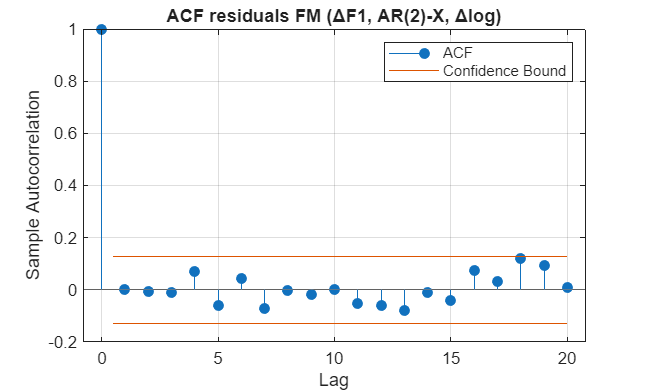



%% =====================================================================
% 9) Trasformazione Δlog forecast → log-livello forecast
% =====================================================================

log_y_hat_DFM = NaN(Ttot_DFM,1);
last_log_train = y_log_mod(T_train_DFM + 2);
log_y_hat_DFM(T_train_DFM) = last_log_train;

for t = T_train_DFM+1:Ttot_DFM
    log_y_hat_DFM(t) = log_y_hat_DFM(t-1) + y_hat_DFM(t);
end

%% =====================================================================
% 10) Diagnostica residui (training)
% =====================================================================

y_train_DFM   = y_dep(1:T_train_DFM);
y_lag_1_tr    = y_lag_1(1:T_train_DFM);
y_lag_2_tr    = y_lag_2(1:T_train_DFM);
F1_train      = F1_reg(1:T_train_DFM);

X_train = [ones(T_train_DFM,1), y_lag_1_tr, y_lag_2_tr, F1_train];
beta_tr_DFM = X_train \ y_train_DFM;

res_DFM = y_train_DFM - X_train * beta_tr_DFM;

figure; autocorr(res_DFM);
title('ACF residuals FM (ΔF1, AR(2)-X, Δlog)');
grid on;

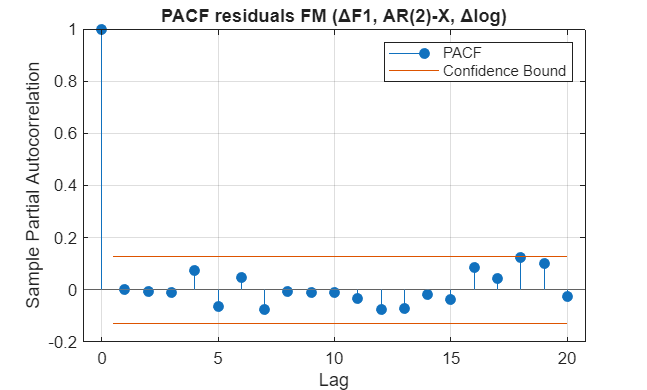


figure; parcorr(res_DFM);
title('PACF residuals FM (ΔF1, AR(2)-X, Δlog)');
grid on;


[h_lb_DFM, p_lb_DFM] = lbqtest(res_DFM);
fprintf('Ljung-Box residuals FM (ΔF1, AR(2), Δlog) – training: h=%d, p=%.4f\n', h_lb_DFM, p_lb_DFM);

Ljung-Box residuals FM (ΔF1, AR(2), Δlog) – training: h=0, p=0.7276


%PROVA SECONDO MODELLO CON DELTA LOG
%Second DFM with two factors: one for US and one for Eu
%after the PCA an AR(2)-X model has been computed 

%% =====================================================================
% 0) PULIZIA
% =====================================================================

date_cut = datetime(2000,1,1);   % lavoriamo dal 2000 in poi

%% =====================================================================
% 1) IMPORTA FRED-MD (USA)
% =====================================================================

optsUS = detectImportOptions("2025-10-md.csv", "VariableNamingRule","preserve");
optsUS = setvartype(optsUS, "sasdate", "datetime");
optsUS = setvaropts(optsUS, "sasdate", "InputFormat","MM/dd/yyyy");

US = readtable("2025-10-md.csv", optsUS);

% Prima riga = codici di trasformazione, elimina
US(1,:) = [];

USdate = US.sasdate;
US.sasdate = [];

us_vars = { ...
    'RPI','W875RX1','DPCERA3M086SBEA','CMRMTSPLx','RETAILx', ...
    'INDPRO','IPFPNSS','IPFINAL','IPCONGD','HOUST','PAYEMS', ...
    'UNRATE', ...
    'CPIAUCSL','CUSR0000SA0L2','CUSR0000SA0L5','PCEPI', ...
    'FEDFUNDS','GS1','GS10', ...
    'UMCSENTx','VIXCLSx'};

XUS_raw = US{:, us_vars};

% Taglio dal 2000
idxUS = USdate >= date_cut;
USdate_cut = USdate(idxUS);
XUS_cut    = XUS_raw(idxUS,:);


%% =====================================================================
% 2) IMPORTA EAdata (Euro Area)
% =====================================================================

optsEA = detectImportOptions("EAdata.xlsx", "VariableNamingRule","preserve");
optsEA = setvartype(optsEA, "Time", "datetime");
optsEA = setvaropts(optsEA, "Time", "InputFormat","dd/MM/yy HH:mm");

EA = readtable("EAdata.xlsx", optsEA);

dates_EA = EA.Time;
dates_EA.Format = "yyyy-MM";

eu_vars = { ...
    'IPMN_EA','IPING_EA','IPCAG_EA','IPCOG_EA','IPNRG_EA', ...
    'HICPNEF_EA','HICPG_EA','HICPNG_EA', ...
    'PPICAG_EA','PPICOG_EA','PPING_EA', ...
    'IRT3M_EA','LTRT_EA', ...
    'ICONFIX_EA','ESENTIX_EA','CCONFIX_EA','BCI_EA','CCI_EA'};

eu_vars = eu_vars(ismember(eu_vars, EA.Properties.VariableNames));
XEA_raw = EA{:, eu_vars};

idxEA = dates_EA >= date_cut;
EAdate_cut = dates_EA(idxEA);
XEA_cut    = XEA_raw(idxEA,:);

fprintf("USA osservazioni >=2000: %d\n", sum(idxUS));

USA osservazioni >=2000: 309


fprintf("EA  osservazioni >=2000: %d\n", sum(idxEA));

EA  osservazioni >=2000: 310




%% =====================================================================
% 3) ALLINEAMENTO USA / EA AL MESE
% =====================================================================

US_month = dateshift(USdate_cut,'start','month');
EA_month = dateshift(EAdate_cut,'start','month');

US_month.Format = "yyyy-MM";
EA_month.Format = "yyyy-MM";

[common_dates, idx_US, idx_EA] = intersect(US_month, EA_month);

X_US = XUS_cut(idx_US,:);
X_EA = XEA_cut(idx_EA,:);


%% =====================================================================
% 4) RIMOZIONE NaN E PANNELLI US/EU PULITI
% =====================================================================

X_all_macro = [X_US, X_EA];
rows_ok     = all(~isnan(X_all_macro),2);

dates_macro = common_dates(rows_ok);
X_US_clean  = X_US(rows_ok,:);
X_EA_clean  = X_EA(rows_ok,:);

[Tmacro, NUS]  = size(X_US_clean);
[~,      NEA]  = size(X_EA_clean);
fprintf("Pannello US pulito: %d×%d, EA pulito: %d×%d\n", Tmacro, NUS, Tmacro, NEA);

Pannello US pulito: 307×21, EA pulito: 307×15


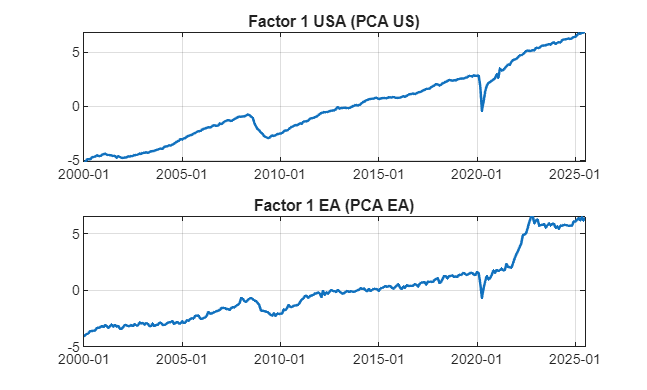



%% =====================================================================
% 5) PCA SEPARATA: USA e EA
% =====================================================================

% ---- USA ----
XUS_std = (X_US_clean - mean(X_US_clean,1)) ./ std(X_US_clean,[],1);
[U_US, S_US, ~] = svd(XUS_std, 'econ');
F_US_all = U_US * S_US;          % fattori USA
F_US_1   = F_US_all(:,1);        % primo fattore USA

% ---- EA ----
XEA_std = (X_EA_clean - mean(X_EA_clean,1)) ./ std(X_EA_clean,[],1);
[U_EA, S_EA, ~] = svd(XEA_std, 'econ');
F_EA_all = U_EA * S_EA;          % fattori EA
F_EA_1   = F_EA_all(:,1);        % primo fattore EA

% (opzionale) grafico fattori
figure;
subplot(2,1,1);
plot(dates_macro, F_US_1,'LineWidth',1.5); grid on;
title('Factor 1 USA (PCA US)','Interpreter','none');
datetick('x','yyyy-mm','keeplimits');

subplot(2,1,2);
plot(dates_macro, F_EA_1,'LineWidth',1.5); grid on;
title('Factor 1 EA (PCA EA)','Interpreter','none');
datetick('x','yyyy-mm','keeplimits');



%% =====================================================================
% 6) IMPORTO CAMBIO EUR/USD E ALLINEO A DATE MACRO
% =====================================================================

FX = readtable("ert_bil_eur_m__custom_18765067_linear_2_0.csv");


FX.TIME_PERIOD = datetime(string(FX.TIME_PERIOD),'InputFormat','yyyy-MM');
FX.TIME_PERIOD.Format = "yyyy-MM";

dates_fx = FX.TIME_PERIOD;
y_level  = FX.OBS_VALUE;
y_log    = log(y_level);

idxFX = dates_fx >= date_cut;
dates_fx_cut = dates_fx(idxFX);
y_log_cut    = y_log(idxFX);

[dates_model, idxMacro, idxFX2] = intersect(dates_macro, dates_fx_cut);

FUS_model = F_US_1(idxMacro);
FEA_model = F_EA_1(idxMacro);
y_log_mod = y_log_cut(idxFX2);

fprintf("Osservazioni comuni macro+FX: %d\n", numel(dates_model));

Osservazioni comuni macro+FX: 307


%% =====================================================================
%% =====================================================================
% 7) COSTRUISCO VARIABILI PER IL DFM A 2 FATTORI SU Δ log-livelli
% Con fattori laggati di 1 periodo (ΔFUS_{t-1}, ΔFEA_{t-1})
%% =====================================================================

% differenze logaritmiche del tasso di cambio
y_full   = diff(y_log_mod);        

% differenze prime dei fattori per stazionarizzare
FUS_full = diff(FUS_model);       
FEA_full = diff(FEA_model);       
dates_f  = dates_model(2:end);    % date aggiornate

% lag di Δy (AR(2))
y_lag_1 = [NaN; y_full(1:end-1)];
y_lag_2 = [NaN; NaN; y_full(1:end-2)];

% elimino prime due osservazioni (mancano Δy_{t-1} e Δy_{t-2})
y_dep   = y_full(3:end);
y_lag_1 = y_lag_1(3:end);
y_lag_2 = y_lag_2(3:end);

% ---- Creazione lag di 1 periodo per i fattori ----
FUS_lag = [NaN; FUS_full(1:end-1)];
FEA_lag = [NaN; FEA_full(1:end-1)];

% Allineamento con Δy
FUS_reg = FUS_lag(3:end);  % ΔFUS_{t-1}
FEA_reg = FEA_lag(3:end);  % ΔFEA_{t-1}

dates_y = dates_f(3:end);

% ---- Definizione dimensioni per train/test ----
Ttot       = length(y_dep);
T_train    = floor(0.8 * Ttot);
idx_test_DFM2 = (T_train+1):Ttot;

fprintf("DFM (2 fattori differenziati, AR(2)-X, Δlog): tot = %d | train = %d | test = %d\n", ...
    Ttot, T_train, Ttot - T_train);

DFM (2 fattori differenziati, AR(2)-X, Δlog): tot = 304 | train = 243 | test = 61



% Commento modello aggiornato
% Δy_t = α + β1 Δy_{t-1} + β2 Δy_{t-2} + γ_US ΔFUS_{t-1} + γ_EA ΔFEA_{t-1} + ε_t


%% =====================================================================
% 8) DFM A 2 FATTORI (AR(2)-X) — EXPANDING WINDOW
% =====================================================================

y_hat_DFM2 = NaN(Ttot,1);

for t = T_train+1:Ttot
    y_est = y_dep(1:t-1);
    X_est = [ones(t-1,1), y_lag_1(1:t-1), y_lag_2(1:t-1), FUS_reg(1:t-1), FEA_reg(1:t-1)];
    beta  = X_est \ y_est;

    X_t = [1, y_lag_1(t), y_lag_2(t), FUS_reg(t), FEA_reg(t)];
    y_hat_DFM2(t) = X_t * beta;
end

% errori forecast Δlog
err_DFM2   = y_dep(idx_test_DFM2) - y_hat_DFM2(idx_test_DFM2);
RMSFE_DFM2 = sqrt(mean(err_DFM2.^2,'omitnan'));
MAFE_DFM2  = mean(abs(err_DFM2),'omitnan');

fprintf("\n=== DFM su Δlog-livello con ΔFUS + ΔFEA (AR(2)-X) ===\n");


=== DFM su Δlog-livello con ΔFUS + ΔFEA (AR(2)-X) ===


fprintf("RMSFE_DFM2 = %.6f\n", RMSFE_DFM2);

RMSFE_DFM2 = 0.015992


fprintf("MAFE_DFM2  = %.6f\n", MAFE_DFM2);

MAFE_DFM2  = 0.012907


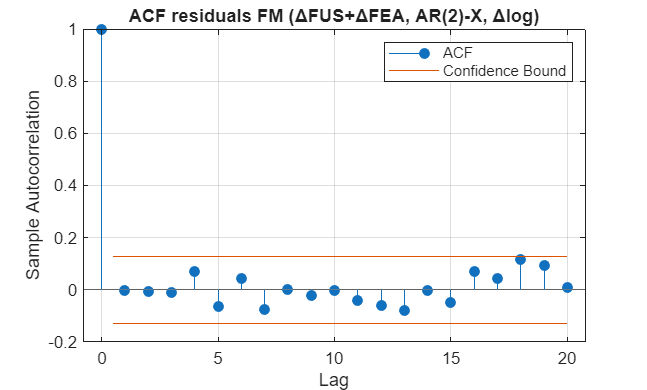


%% =====================================================================
% 9) Trasformazione Δlog forecast → log-livello forecast
% =====================================================================

log_y_hat_DFM2 = NaN(Ttot,1);
last_log_train = y_log_mod(T_train + 2);  
log_y_hat_DFM2(T_train) = last_log_train;

for t = T_train+1:Ttot
    log_y_hat_DFM2(t) = log_y_hat_DFM2(t-1) + y_hat_DFM2(t);
end

%% =====================================================================
% 10) Diagnostica residui (training)
% =====================================================================

y_train     = y_dep(1:T_train);
y_lag_1_tr  = y_lag_1(1:T_train);
y_lag_2_tr  = y_lag_2(1:T_train);
FUS_tr      = FUS_reg(1:T_train);
FEA_tr      = FEA_reg(1:T_train);

X_train = [ones(T_train,1), y_lag_1_tr, y_lag_2_tr, FUS_tr, FEA_tr];
beta_tr = X_train \ y_train;

res_DFM2 = y_train - X_train*beta_tr;

figure; autocorr(res_DFM2);
title('ACF residuals FM (ΔFUS+ΔFEA, AR(2)-X, Δlog)');
grid on;

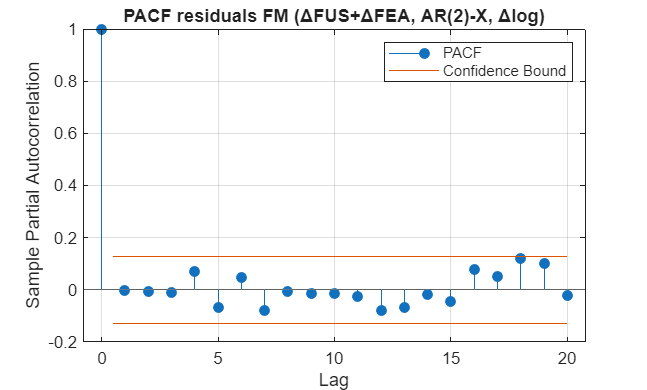


figure; parcorr(res_DFM2);
title('PACF residuals FM (ΔFUS+ΔFEA, AR(2)-X, Δlog)');
grid on;


[h_lb, p_lb] = lbqtest(res_DFM2);
fprintf('Ljung-Box residuals FM (ΔFUS+ΔFEA, AR(2), Δlog) – training: h=%d, p=%.4f\n', h_lb, p_lb);

Ljung-Box residuals FM (ΔFUS+ΔFEA, AR(2), Δlog) – training: h=0, p=0.7290


%PROVA NUOVO AR(2)-X CORRETTO
%
%% =====================================================================
% 0) PULIZIA
% =====================================================================

date_cut = datetime(2000,1,1);   % lavoriamo dal 2000 in poi

%% =====================================================================
% 1) IMPORTA FRED-MD (USA) e prendi UMCSENTx
% =====================================================================

optsUS = detectImportOptions("2025-10-md.csv", "VariableNamingRule","preserve");
optsUS = setvartype(optsUS, "sasdate", "datetime");
optsUS = setvaropts(optsUS, "sasdate", "InputFormat","MM/dd/yyyy");

US = readtable("2025-10-md.csv", optsUS);

% prima riga = codici di trasformazione -> la eliminiamo
US(1,:) = [];

USdate = US.sasdate;
US.sasdate = [];

% variabile di interesse: UMCSENTx (sentiment USA)
if ~ismember("UMCSENTx", US.Properties.VariableNames)
    error("Nel file FRED-MD non trovo la variabile 'UMCSENTx'. Controlla il nome.");
end

UMC_US = US.UMCSENTx;

% taglio dal 2000 in poi
idxUS = USdate >= date_cut;
USdate_cut = USdate(idxUS);
UMC_US_cut = UMC_US(idxUS);


%% =====================================================================
% 2) IMPORTA EAdata.xlsx (Euro Area) e prendi ICONFIX_EA
% =====================================================================

optsEA = detectImportOptions("EAdata.xlsx", "VariableNamingRule","preserve");
optsEA = setvartype(optsEA, "Time", "datetime");
optsEA = setvaropts(optsEA, "Time", "InputFormat","dd/MM/yy HH:mm");

EA = readtable("EAdata.xlsx", optsEA);

dates_EA = EA.Time;
dates_EA.Format = "yyyy-MM";

if ~ismember("ICONFIX_EA", EA.Properties.VariableNames)
    error("Nel file EAdata.xlsx non trovo la variabile 'ICONFIX_EA'. Controlla il nome della colonna.");
end

ICON_EA = EA.ICONFIX_EA;

idxEA = dates_EA >= date_cut;
EAdate_cut  = dates_EA(idxEA);
ICON_EA_cut = ICON_EA(idxEA);


%% =====================================================================
% 3) ALLINEO UMCSENTx (USA) E ICONFIX_EA (EA) ALLE STESSE DATE
% =====================================================================

US_m = dateshift(USdate_cut,'start','month');
EA_m = dateshift(EAdate_cut,'start','month');

US_m.Format = "yyyy-MM";
EA_m.Format = "yyyy-MM";

[common_macro_dates, idx_US_m, idx_EA_m] = intersect(US_m, EA_m);

UMC_aligned  = UMC_US_cut(idx_US_m);
ICON_aligned = ICON_EA_cut(idx_EA_m);

fprintf("Osservazioni comuni USA(E)–EA(E) dal 2000: %d\n", numel(common_macro_dates));

Osservazioni comuni USA(E)–EA(E) dal 2000: 309



%% =====================================================================
% 3B) TEST DI STAZIONARIETÀ (ADF) SU UMC E ICON IN LIVELLI
% =====================================================================

fprintf("\n=============================================================\n");

fprintf("            TEST DI STAZIONARIETÀ (ADF) SU UMC E ICON        \n");

            TEST DI STAZIONARIETÀ (ADF) SU UMC E ICON        


fprintf("=============================================================\n");


% Test ADF sulla serie UMC (USA) in livelli
fprintf("\n=== Test ADF sulla serie UMC (USA) in livelli ===\n");


=== Test ADF sulla serie UMC (USA) in livelli ===


try
    [h_umc, p_umc] = adftest(UMC_aligned);
    fprintf("ADF UMC: h=%d (1=stazionaria), p=%.4f\n", h_umc, p_umc);
catch
    warning("Funzione adftest non disponibile. Verifica che l'Econometrics Toolbox sia installato.");
end

ADF UMC: h=0 (1=stazionaria), p=0.2093



% Test ADF sulla serie ICONFIX_EA (EA) in livelli
fprintf("\n=== Test ADF sulla serie ICONFIX_EA (EA) in livelli ===\n");


=== Test ADF sulla serie ICONFIX_EA (EA) in livelli ===


try
    [h_icon, p_icon] = adftest(ICON_aligned);
    fprintf("ADF ICON: h=%d (1=stazionaria), p=%.4f\n", h_icon, p_icon);
catch
    warning("Funzione adftest non disponibile.");
end

ADF ICON: h=1 (1=stazionaria), p=0.0431



fprintf("=============================================================\n\n");

%% =====================================================================
% 3C) TEST KPSS SU UMC E ICON IN LIVELLI
% =====================================================================

fprintf("\n=============================================================\n");

fprintf("                TEST DI STAZIONARIETÀ (KPSS)                 \n");

                TEST DI STAZIONARIETÀ (KPSS)                 


fprintf("=============================================================\n");


% KPSS sulla serie UMC (USA) in livelli
fprintf("\n=== Test KPSS sulla serie UMC (USA) in livelli ===\n");


=== Test KPSS sulla serie UMC (USA) in livelli ===


try
    [h_kpss_umc, p_kpss_umc] = kpsstest(UMC_aligned); 
    fprintf("KPSS UMC: h=%d (1=NON stazionaria), p=%.4f\n", h_kpss_umc, p_kpss_umc);
catch
    warning("Funzione kpsstest non disponibile. Richiede Econometrics Toolbox.");
end

KPSS UMC: h=1 (1=NON stazionaria), p=0.0100



% KPSS sulla serie ICON (EA) in livelli
fprintf("\n=== Test KPSS sulla serie ICONFIX_EA (EA) in livelli ===\n");


=== Test KPSS sulla serie ICONFIX_EA (EA) in livelli ===


try
    [h_kpss_icon, p_kpss_icon] = kpsstest(ICON_aligned);
    fprintf("KPSS ICON: h=%d (1=NON stazionaria), p=%.4f\n", h_kpss_icon, p_kpss_icon);
catch
    warning("Funzione kpsstest non disponibile.");
end

KPSS ICON: h=1 (1=NON stazionaria), p=0.0100



fprintf("=============================================================\n\n");



%% =====================================================================
% 4) IMPORTA CAMBIO EUR/USD E ALLINEA ALLE DATE MACRO
%% =====================================================================

FX = readtable("ert_bil_eur_m__custom_18765067_linear_2_0.csv");


FX.TIME_PERIOD = datetime(string(FX.TIME_PERIOD),'InputFormat','yyyy-MM');
FX.TIME_PERIOD.Format = "yyyy-MM";

dates_fx = FX.TIME_PERIOD;
y_level  = FX.OBS_VALUE;
y_log    = log(y_level);

idxFX = dates_fx >= date_cut;
dates_fx_cut = dates_fx(idxFX);
y_log_cut    = y_log(idxFX);

[dates_model, idxMacro, idxFX2] = intersect(common_macro_dates, dates_fx_cut);

% allineo tutte e tre le serie:
UMC_model  = UMC_aligned(idxMacro);   % UMCSENTx (USA)
ICON_model = ICON_aligned(idxMacro);  % ICONFIX_EA (EA)
y_log_mod  = y_log_cut(idxFX2);       % log(EUR/USD)

% --- Differenze prime per stazionarizzare y e le serie esplicative ---
y_full   = diff(y_log_mod);           % Δlog(EUR/USD)
UMC_full = diff(UMC_model);           % ΔUMCSENTx
ICON_full= diff(ICON_model);          % ΔICONFIX_EA

dates_f  = dates_model(2:end);       % date aggiornate
%% =====================================================================
%% =====================================================================
% 5) COSTRUISCO LE VARIABILI PER L'ARX (AR(2)-X) SU Δlog
%% =====================================================================

% --- Δlog(EUR/USD) e lag ---
y_full   = diff(y_log_mod);       % Δy_t
UMC_full = diff(UMC_model);       % ΔUMCSENTx
ICON_full= diff(ICON_model);      % ΔICONFIX_EA

% Allineiamo tutte le serie: Δy t-2, Δy t-1, ΔUMC t-1, ΔICON t-1
% Creiamo lag di Δy
y_lag_1 = [NaN; y_full(1:end-1)];   % Δy_{t-1}
y_lag_2 = [NaN; NaN; y_full(1:end-2)]; % Δy_{t-2}

% Lag di regressori esogeni: prendiamo ΔUMC_t-1 e ΔICON_t-1 per allineare
UMC_lag = [NaN; UMC_full(1:end-1)];
ICON_lag= [NaN; ICON_full(1:end-1)];

% Eliminiamo prime due osservazioni (dove ci sono NaN nei lag di y)
y_dep    = y_full(3:end);        % Δy_t
y_lag_1  = y_lag_1(3:end);       % Δy_{t-1}
y_lag_2  = y_lag_2(3:end);       % Δy_{t-2}
UMC_reg  = UMC_lag(3:end);       % ΔUMC_{t-1}
ICON_reg = ICON_lag(3:end);      % ΔICON_{t-1}

dates_y  = dates_model(3:end);   % date aggiornate

% opzionale: standardizziamo i regressori
UMC_reg_std  = (UMC_reg  - mean(UMC_reg,'omitnan')) ./ std(UMC_reg,'omitnan');
ICON_reg_std = (ICON_reg - mean(ICON_reg,'omitnan')) ./ std(ICON_reg,'omitnan');

Ttot    = length(y_dep);
T_train = floor(0.8 * Ttot);
idx_test_ARX = (T_train+1):Ttot;
%% =====================================================================
% 6) ARX(2) CON ΔUMCSENTx E ΔICONFIX_EA — EXPANDING WINDOW
%% =====================================================================

y_hat_ARX = NaN(Ttot,1);

for t = T_train+1:Ttot
    y_est = y_dep(1:t-1);
    X_est = [ones(t-1,1), y_lag_1(1:t-1), y_lag_2(1:t-1), ...
             UMC_reg_std(1:t-1), ICON_reg_std(1:t-1)];
         
    beta = X_est \ y_est;   % OLS
    
    X_t = [1, y_lag_1(t), y_lag_2(t), UMC_reg_std(t), ICON_reg_std(t)];
    y_hat_ARX(t) = X_t * beta;  % previsione di Δy_t
end

% errori forecast Δlog
err_ARX   = y_dep(idx_test_ARX) - y_hat_ARX(idx_test_ARX);
RMSFE_ARX = sqrt(mean(err_ARX.^2,'omitnan'));
MAFE_ARX  = mean(abs(err_ARX),'omitnan');

fprintf('\n=== ARX(2) con ΔUMCSENTx e ΔICONFIX_EA su Δlog ===\n');


=== ARX(2) con ΔUMCSENTx e ΔICONFIX_EA su Δlog ===


fprintf('RMSFE_ARX = %.6f\n', RMSFE_ARX);

RMSFE_ARX = 0.015853


fprintf('MAFE_ARX  = %.6f\n', MAFE_ARX);

MAFE_ARX  = 0.012749


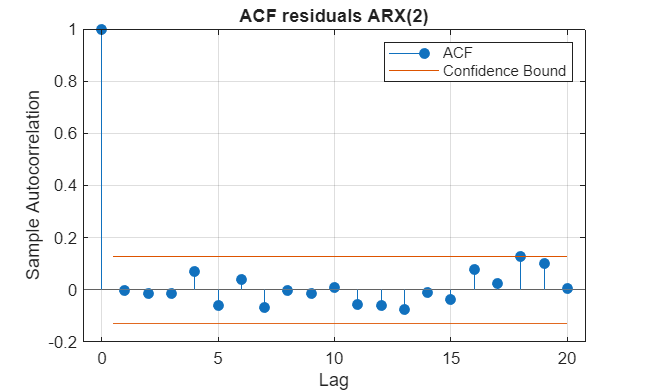




%% =====================================================================
% 7) DIAGNOSTICA RESIDUI (SOLO TRAINING)
% =====================================================================

y_train      = y_dep(1:T_train);
y_lag_1_tr   = y_lag_1(1:T_train);
y_lag_2_tr   = y_lag_2(1:T_train);
UMC_tr       = UMC_reg_std(1:T_train);
ICON_tr      = ICON_reg_std(1:T_train);

X_train = [ones(T_train,1), y_lag_1_tr, y_lag_2_tr, UMC_tr, ICON_tr];
beta_tr = X_train \ y_train;

res_ARX = y_train - X_train*beta_tr;

figure; autocorr(res_ARX);
title('ACF residuals ARX(2)');
grid on;

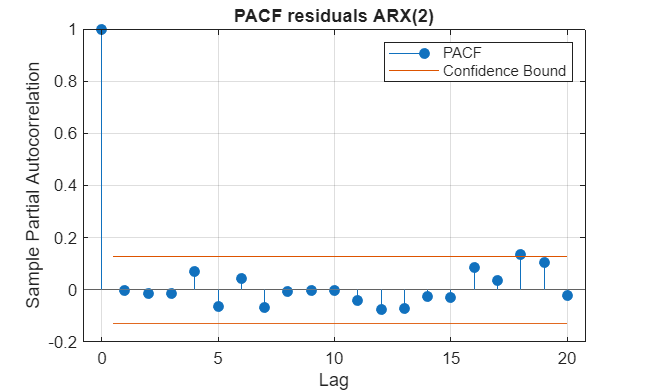


figure; parcorr(res_ARX);
title('PACF residuals ARX(2)');
grid on;


[h_lb_ARX, p_lb_ARX] = lbqtest(res_ARX);
fprintf('Ljung-Box residuals ARX(2) (training): h=%d, p=%.4f\n', h_lb_ARX, p_lb_ARX);

Ljung-Box residuals ARX(2) (training): h=0, p=0.6978


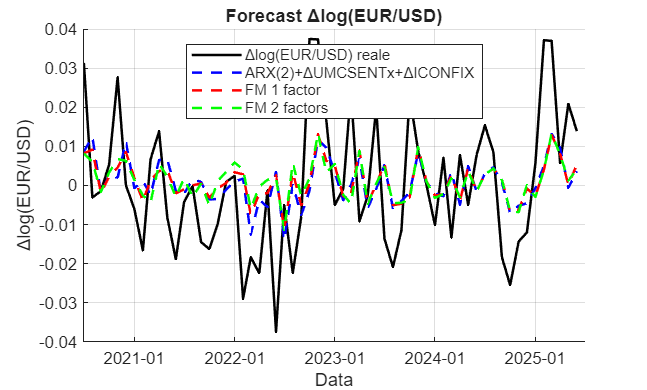

%PLOT DI TUTTI I FORECAST IN DIFFERENZE LOG
%% --- Trova primo indice valido per ciascun forecast ---
idx_ARX = find(~isnan(y_hat_ARX), 1, 'first');
idx_DFM1 = find(~isnan(y_hat_DFM), 1, 'first');
idx_DFM2 = find(~isnan(y_hat_DFM2), 1, 'first');

% Primo indice comune disponibile
first_idx_common = max([idx_ARX, idx_DFM1, idx_DFM2]);

% Estrai le serie dal primo indice comune
y_ARX_sub = y_hat_ARX(first_idx_common:end);
y_DFM1_sub = y_hat_DFM(first_idx_common:end);
y_DFM2_sub = y_hat_DFM2(first_idx_common:end);
y_real_sub = y_dep(first_idx_common:end);
dates_sub = dates_y(first_idx_common:end);

% Trova lunghezza minima comune
N = min([length(y_ARX_sub), length(y_DFM1_sub), length(y_DFM2_sub), length(y_real_sub)]);

% Ritaglia tutte le serie alla stessa lunghezza
y_ARX_plot  = y_ARX_sub(1:N);
y_DFM1_plot = y_DFM1_sub(1:N);
y_DFM2_plot = y_DFM2_sub(1:N);
y_real_plot = y_real_sub(1:N);
dates_plot  = dates_sub(1:N);

%% --- Plot ---
figure; hold on; grid on;

% Serie reale Δlog(EUR/USD)
plot(dates_plot, y_real_plot, 'k', 'LineWidth', 1.5);

% Forecast dei modelli
plot(dates_plot, y_ARX_plot, '--b', 'LineWidth', 1.5);
plot(dates_plot, y_DFM1_plot, '--r', 'LineWidth', 1.5);
plot(dates_plot, y_DFM2_plot, '--g', 'LineWidth', 1.5);

legend('Δlog(EUR/USD) reale', 'ARX(2)+ΔUMCSENTx+ΔICONFIX', ...
       'FM 1 factor', 'FM 2 factors', 'Location','best');
title('Forecast Δlog(EUR/USD)');
xlabel('Data'); ylabel('Δlog(EUR/USD)');
datetick('x','yyyy-mm','keeplimits');

% --------------------------
% Modelli inclusi MA
% --------------------------
models = {
    'RW drift', res_rw;
    'RW no drift', res_rw0;
    'AR(1)', res_ar1;
    'AR(2)', res_ar2;
    'AR(3)', res_ar3;
    'ARIMA(1,1,1)', res_111;
    'ARX', res_ARX;
    'DFM', res_DFM;
    'DFM2', res_DFM2;
    'MA(1)', res_ma1;       % aggiunta MA(1)
    'MA(2)', res_ma2        % aggiunta MA(2)
};

for j = 1:size(models,1)

    name = models{j,1};
    res  = models{j,2};

    fprintf("\n==============================================\n");
    fprintf("  MODEL: %s\n", name);
    fprintf("==============================================\n");

    %% Test media = 0
    [h_mu,p_mu] = ttest(res);
    fprintf("Mean of the residuals = %.6f | p-value t-test = %.4f\n", mean(res), p_mu);

    %% White test
    e2 = res.^2;
    X = [ones(size(res)), res, res.^2];
    [~,~,~,~,stats] = regress(e2, X);
    LM = numel(res) * stats(1);
    p_white = 1 - chi2cdf(LM,2);
    fprintf("White test p-value = %.4f\n", p_white);

    %% ARCH test
    [h_arch,p_arch] = archtest(res);
    fprintf("ARCH p-value = %.4f\n", p_arch);

end

  MODEL: RW drift


Mean of the residuals = 0.000005 | p-value t-test = 0.9973


White test p-value = 0.0000


ARCH p-value = 0.0523


  MODEL: RW no drift


Mean of the residuals = 0.000622 | p-value t-test = 0.6682


White test p-value = 0.0000


ARCH p-value = 0.0695


  MODEL: AR(1)


Mean of the residuals = -0.000012 | p-value t-test = 0.9931


White test p-value = 0.0000


ARCH p-value = 0.8577


  MODEL: AR(2)


Mean of the residuals = 0.000004 | p-value t-test = 0.9979


White test p-value = 0.0000


ARCH p-value = 0.9685


  MODEL: AR(3)


Mean of the residuals = -0.000000 | p-value t-test = 0.9998


White test p-value = 0.0000


ARCH p-value = 0.9561


  MODEL: ARIMA(1,1,1)


Mean of the residuals = -0.000025 | p-value t-test = 0.9853


White test p-value = 0.0000


ARCH p-value = 0.9250


  MODEL: ARX


Mean of the residuals = -0.000000 | p-value t-test = 1.0000


White test p-value = 0.0000


ARCH p-value = 0.9600


  MODEL: DFM


Mean of the residuals = 0.000000 | p-value t-test = 1.0000


White test p-value = 0.0000


ARCH p-value = 0.9730


  MODEL: DFM2


Mean of the residuals = 0.000000 | p-value t-test = 1.0000


White test p-value = 0.0000


ARCH p-value = 0.9869


  MODEL: MA(1)


Mean of the residuals = -0.000046 | p-value t-test = 0.9732


White test p-value = 0.0000


ARCH p-value = 0.9053


  MODEL: MA(2)


Mean of the residuals = -0.000051 | p-value t-test = 0.9703


White test p-value = 0.0000


ARCH p-value = 0.9415


%% ============================================================
%  TABELLA CON RMSFE, MAFE E RATIO RISPETTO AL BENCHMARK AR(2)
% ============================================================

% Controllo che il benchmark AR(2) esista
if ~exist('RMSFE_ar2','var') || ~exist('MAFE_ar2','var')
    error('Il benchmark AR(2) (RMSFE_ar2, MAFE_ar2) non è definito nel workspace.');
end

benchmark_RMSFE = RMSFE_ar2;
benchmark_MAFE  = MAFE_ar2;

% Contenitori
model_names = {};
rmsfe_vec   = [];
mafe_vec    = [];


% ---------- AR(2) - benchmark ----------
if exist('RMSFE_ar2','var') && exist('MAFE_ar2','var')
    model_names{end+1,1} = 'ARIMA(2,1,0)  (benchmark)';
    rmsfe_vec(end+1,1)   = RMSFE_ar2;
    mafe_vec(end+1,1)    = MAFE_ar2;
end

% ---------- ARX (UMC + ICON) ----------
if exist('RMSFE_ARX','var') && exist('MAFE_ARX','var')
    model_names{end+1,1} = 'ARX (UMC + ICON)';
    rmsfe_vec(end+1,1)   = RMSFE_ARX;
    mafe_vec(end+1,1)    = MAFE_ARX;
end

% ---------- DFM 1 fattore ----------
if exist('RMSFE_DFM','var') && exist('MAFE_DFM','var')
    model_names{end+1,1} = 'DFM (1 factor)';
    rmsfe_vec(end+1,1)   = RMSFE_DFM;
    mafe_vec(end+1,1)    = MAFE_DFM;
end

% ---------- DFM 2 fattori ----------
if exist('RMSFE_DFM2','var') && exist('MAFE_DFM2','var')
    model_names{end+1,1} = 'DFM 2 factors (US+EA)';
    rmsfe_vec(end+1,1)   = RMSFE_DFM2;
    mafe_vec(end+1,1)    = MAFE_DFM2;
end

% ---------------------------------------------------------
%  Calcolo dei RATIO rispetto al benchmark AR(2)
% ---------------------------------------------------------
RMSFE_ratio = rmsfe_vec ./ benchmark_RMSFE;
MAFE_ratio  = mafe_vec  ./ benchmark_MAFE;

% ---------------------------------------------------------
%  Costruzione tabella
% ---------------------------------------------------------
Results_Models = table( model_names, ...
                        rmsfe_vec, mafe_vec, ...
                        RMSFE_ratio, MAFE_ratio, ...
    'VariableNames', {'Model','RMSFE','MAFE','RMSFE_ratio_AR2','MAFE_ratio_AR2'});

disp('===============================================');

disp('CONFRONTO MODELLI (benchmark = ARIMA(2,1,0))');

CONFRONTO MODELLI (benchmark = ARIMA(2,1,0))


disp('RMSFE_ratio_AR2 < 1  → meglio di AR(2)');

RMSFE_ratio_AR2 < 1  → meglio di AR(2)


disp('MAFE_ratio_AR2  < 1  → meglio di AR(2)');

MAFE_ratio_AR2  < 1  → meglio di AR(2)


disp('===============================================');

disp(Results_Models);

                Model                 RMSFE        MAFE      RMSFE_ratio_AR2    MAFE_ratio_AR2
    _____________________________    ________    ________    _______________    ______________

    {'ARIMA(2,1,0)  (benchmark)'}    0.015548    0.012474             1                  1    
    {'ARX (UMC + ICON)'         }    0.015853    0.012749        1.0197              1.022    
    {'DFM (1 factor)'           }     0.01589    0.012631         1.022             1.0126    
    {'DFM 2 factors (US+EA)'    }    0.015992    0.012907        1.0286             1.0347    




%%% =====================================================================
% FORECAST IN LOG-LIVELLO: ARIMA(2,1,0), DFM (1F, 2F) e ARX(2)
% =====================================================================

nLag = 2;                 
T_full = length(y_log_mod);  

%% --- ARIMA(2,1,0) ---
dates_test_arima = dates(T0+1:end);
logy_hat_arima   = fore_ar2(T0+1:end);   % già log-level

% Shift indietro solo ARIMA per allinearsi agli altri modelli
dates_test_arima_shifted = dates_test_arima - calmonths(1);

%% --- DFM 1 fattore (ΔF1 laggato) ---
t_test_DFM1_safe = idx_test_DFM(t_test_DFM1 + nLag <= T_full);

Unrecognized function or variable 't_test_DFM1'.

dates_DFM1_hat = dates_model(t_test_DFM1_safe + nLag);
logy_hat_DFM1_level = y_log_mod(t_test_DFM1_safe + nLag) + y_hat_DFM(t_test_DFM1_safe);

%% --- DFM 2 fattori (ΔF1 e ΔF2 laggati) ---
t_test_DFM2_safe = idx_test_DFM2(t_test_DFM2 + nLag <= T_full);
dates_DFM2_hat = dates_model(t_test_DFM2_safe + nLag);
logy_hat_DFM2_level = y_log_mod(t_test_DFM2_safe + nLag) + y_hat_DFM2(t_test_DFM2_safe);

%% --- ARX(2) (UMC + ICON) ---
t_test_ARX_safe = idx_test_ARX(t_test_ARX + nLag <= T_full);
dates_ARX_hat = dates_model(t_test_ARX_safe + nLag);
logy_hat_ARX_level = y_log_mod(t_test_ARX_safe + nLag) + y_hat_ARX(t_test_ARX_safe);

%% =====================================================================
% GRAFICO: serie originale + forecast in log-livello
% =====================================================================
figure; hold on; grid on;

% Serie originale in log-livello
plot(dates, logy, 'k', 'LineWidth', 1.4);

% ARIMA(2,1,0) (shiftato)
plot(dates_test_arima_shifted, logy_hat_arima, '--b', 'LineWidth', 1.4);

% DFM 1 fattore
plot(dates_DFM1_hat, logy_hat_DFM1_level, '--r', 'LineWidth', 1.4);

% DFM 2 fattori
plot(dates_DFM2_hat, logy_hat_DFM2_level, '--m', 'LineWidth', 1.4);

% ARX(2)
plot(dates_ARX_hat, logy_hat_ARX_level, '--g', 'LineWidth', 1.4);

% Linea separazione train/test
xline(dates(T0),'--k','Train/Test split','LineWidth',1.2);

legend('Actual log(EUR/USD)', 'ARIMA(2,1,0)', 'FM 1 factor', 'FM 2 factors', 'ARX(2)', 'Location','best');
xlabel('Year'); ylabel('log(EUR/USD)');
title('EUR/USD log-level: forecasts of ARIMA, FMs and ARX (converted from Δlog)');
datetick('x','yyyy','keeplimits');




%% =====================================================================
%  PLOT DI TUTTI I FORECAST IN LIVELLI LOG (allineati)
%  Actual log(EUR/USD) + ARIMA(2,1,0) + DFM1 + DFM2 + ARX
% =====================================================================

% Indici comuni usati nel grafico in Δlog
t_idx = first_idx_common : (first_idx_common + N - 1);

% Date corrispondenti nel mondo "macro" (uguali a dates_y dei forecast)
dates_level = dates_y(t_idx);

% -------------------------
% 1) Serie reale in log-livello
% -------------------------
log_real_level = y_log_mod(t_idx + 3);   % log y_k reale

% -------------------------
% 2) Forecast DFM1, DFM2, ARX in log-livello
% log y_k^hat = log y_{k-1} (reale) + Δlog y_k^hat
% -------------------------
log_DFM1_level = y_log_mod(t_idx + 2) + y_hat_DFM(t_idx);
log_DFM2_level = y_log_mod(t_idx + 2) + y_hat_DFM2(t_idx);
log_ARX_level  = y_log_mod(t_idx + 2) + y_hat_ARX(t_idx);

% -------------------------
% 3) ARIMA(2,1,0) (già in log-livello)
% -------------------------
dates_test_arima   = dates(T0+1:end);        % date del test univariato
logy_hat_arima     = fore_ar2(T0+1:end);     % forecast log-level ARIMA(2,1,0)

% Shift di 1 periodo indietro per allineare ARIMA con i modelli Δlog
dates_test_arima_shifted = dates_test_arima - calmonths(1);

% Interseco le date per avere le stesse osservazioni
[dates_final, idx_level, idx_arima] = intersect(dates_level, dates_test_arima_shifted);

% Sottocampiono tutte le serie
log_real_final  = log_real_level(idx_level);
log_DFM1_final  = log_DFM1_level(idx_level);
log_DFM2_final  = log_DFM2_level(idx_level);
log_ARX_final   = log_ARX_level(idx_level);
log_ARIMA_final = logy_hat_arima(idx_arima);

% -------------------------
% 4) Grafico in livelli log
% -------------------------
figure; hold on; grid on;

plot(dates_final, log_real_final, 'k',  'LineWidth', 1.5);  % reale
plot(dates_final, log_ARIMA_final, '--b', 'LineWidth', 1.4);% ARIMA(2,1,0)
plot(dates_final, log_DFM1_final,  '--r', 'LineWidth', 1.4);% DFM 1F
plot(dates_final, log_DFM2_final,  '--m', 'LineWidth', 1.4);% DFM 2F
plot(dates_final, log_ARX_final,   '--g', 'LineWidth', 1.4);% ARX

legend('Actual log(EUR/USD)', ...
       'ARIMA(2,1,0)', ...
       'FM 1 factor', ...
       'FM 2 factors', ...
       'ARX(2)', ...
       'Location','best');

xlabel('Year');
ylabel('log(EUR/USD)');
title('Forecasts in log-levels – ARIMA vs FMs vs ARX');
datetick('x','yyyy-mm','keeplimits');
